clc                     % clear command window
clear                   % clear MATLAB workspace
clf

[robotArduino]= SETUPARDUINO ('COM3') 

robotArduino =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Nano33BLE'
         AvailablePins: {'D0-D13', 'A0-A7'}
  AvailableDigitalPins: {'D0-D13', 'A0-A7'}
      AvailablePWMPins: {'D0-D13'}
   AvailableAnalogPins: {'A0-A3', 'A6-A7'}
    AvailableI2CBusIDs: [0, 1]
AvailableSerialPortIDs: [1]
             Libraries: {'I2C', 'Servo'}
Show all properties


steerServo = servo(robotArduino, 'D5', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
driveServo = servo(robotArduino, 'D3', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
panServo = servo(robotArduino, 'D6', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);

writePosition(steerServo, 0.5);      % always start servo-command at 0.5
writePosition(driveServo, 0.3);      % always start servo-command at 0.5
writePosition(panServo, 0.5);        % always start servo-command at 0.5
pause(3.0);                          % wait for Arduino to send stable pwm
warning ('actuators live');

clear lid
lid = LIDAR('COM6')

lid =   LIDAR with properties:

        lidar: [1×1 serial]
     pol_data: []
    cart_data: []


lidar_data = lid.scan(5000);

lid.close()

cam = Camera();

obj =   Camera with properties:

           cam: [1×1 webcam]
    intrinsics: [1×1 cameraIntrinsics]
       tagSize: []


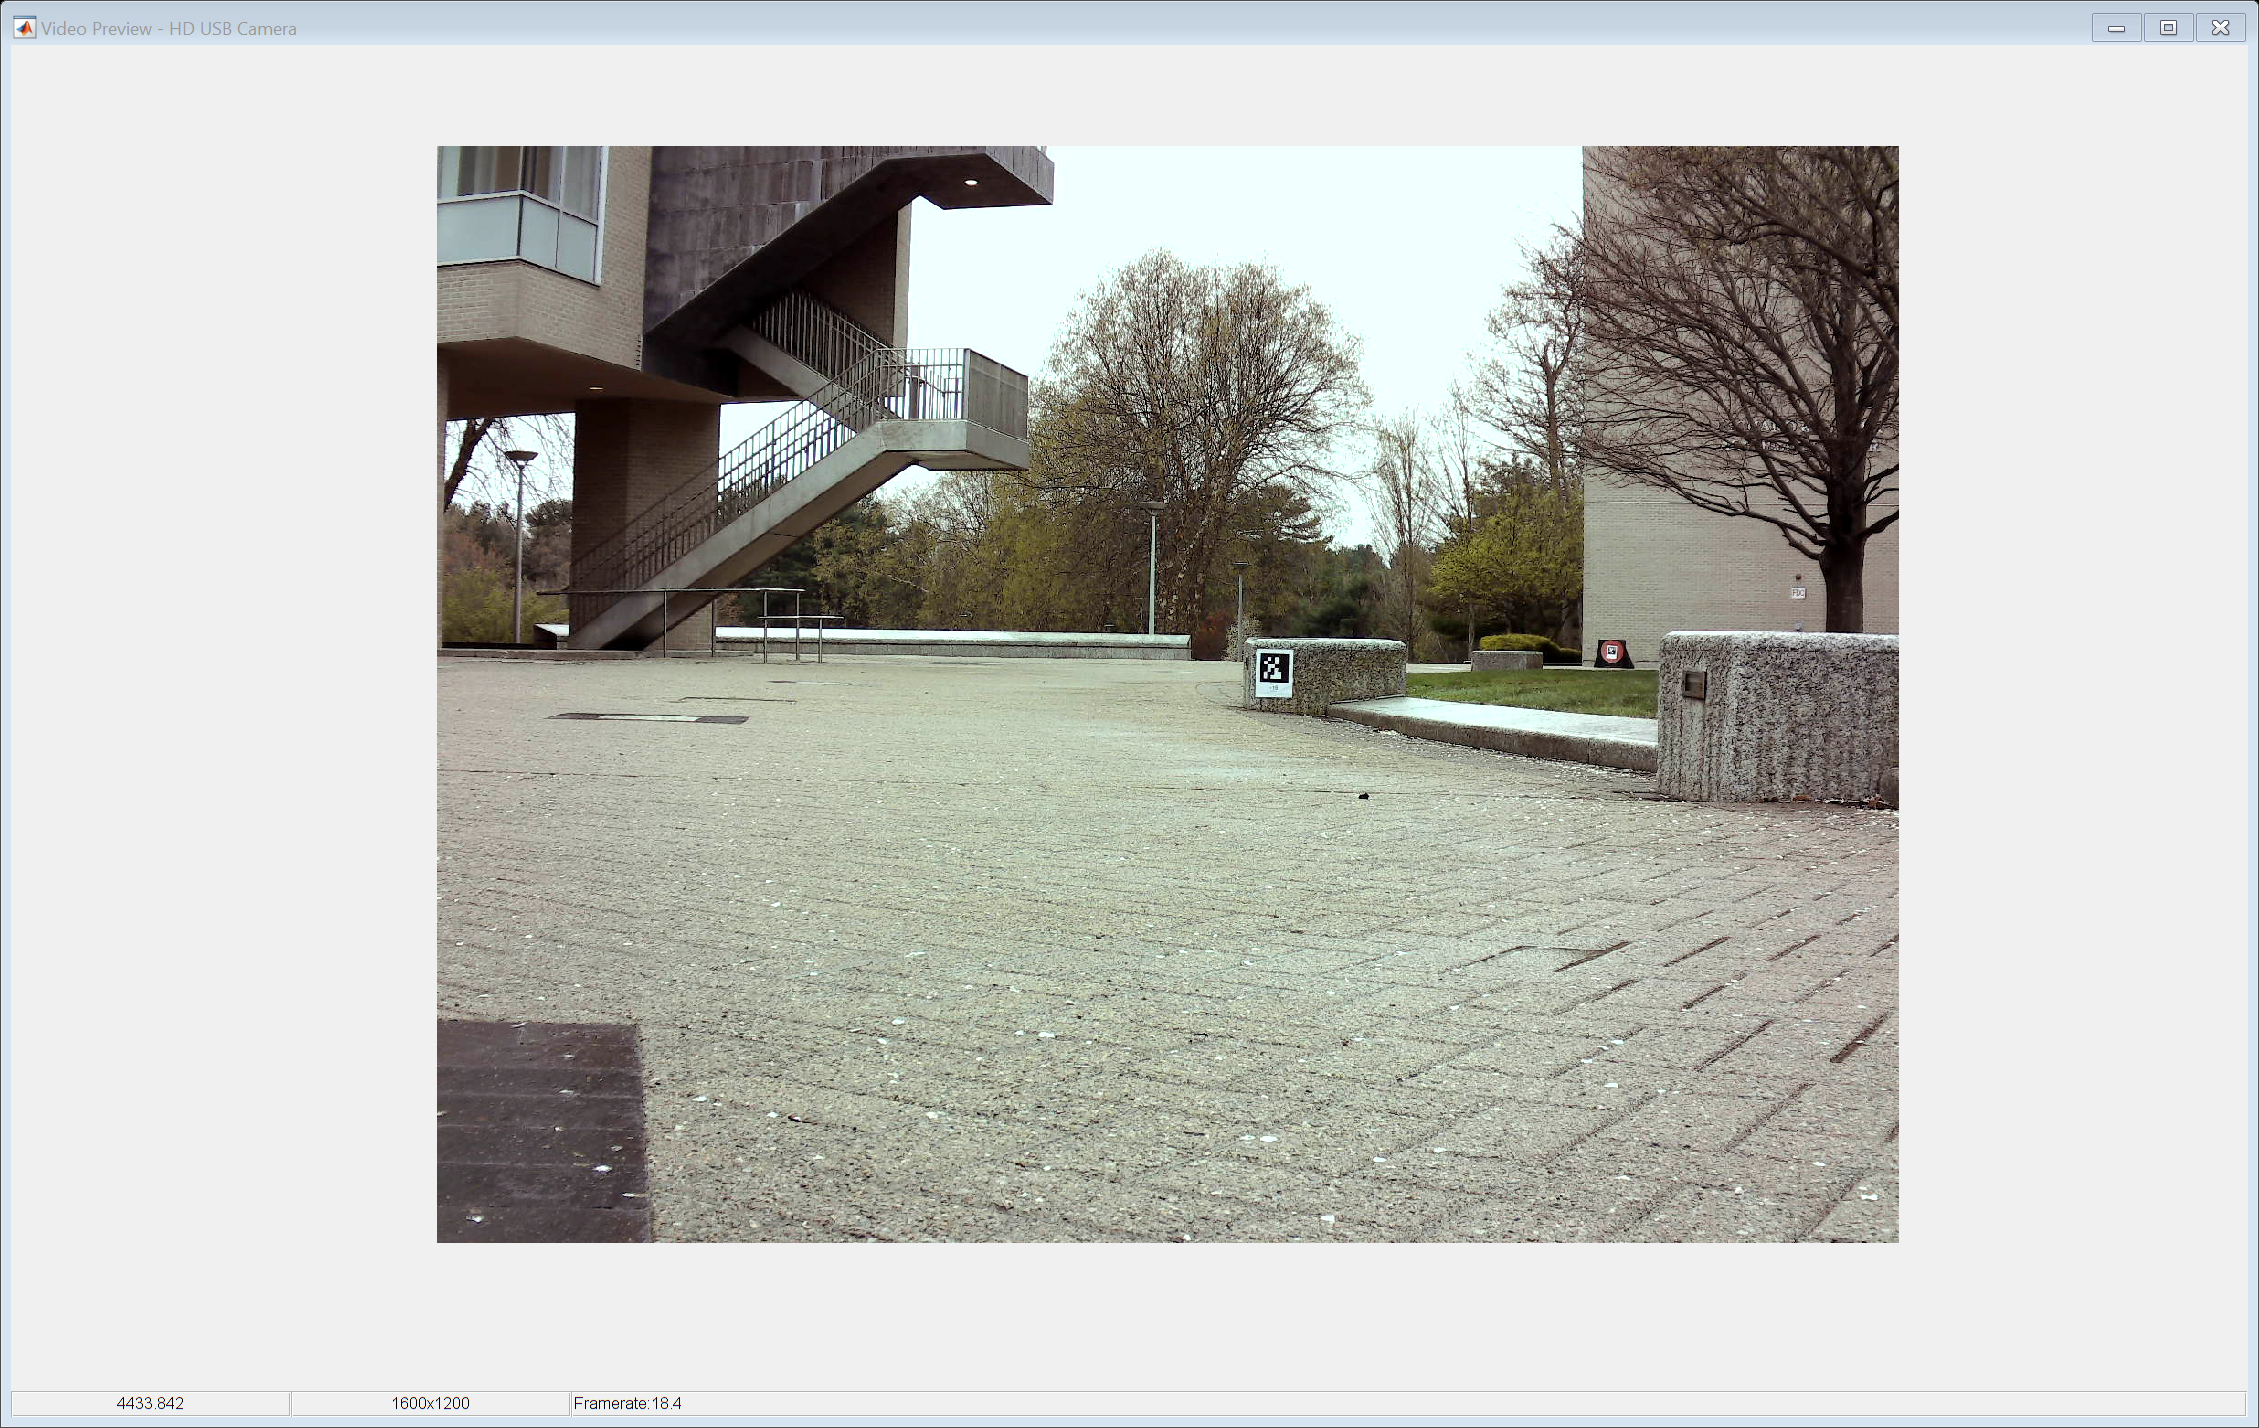

cam.cam.Sharpness = 6;
cam.cam.Exposure = -6;  %%% CALIBRATE THIS ON DEMO DAY
cam.show()

RANSAC fit

% calibrate to 0.1 - 0.3 - 0.9
writePosition(driveServo, 0.3);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.52);
writePosition(panServo, 0.51);

## Outer Course

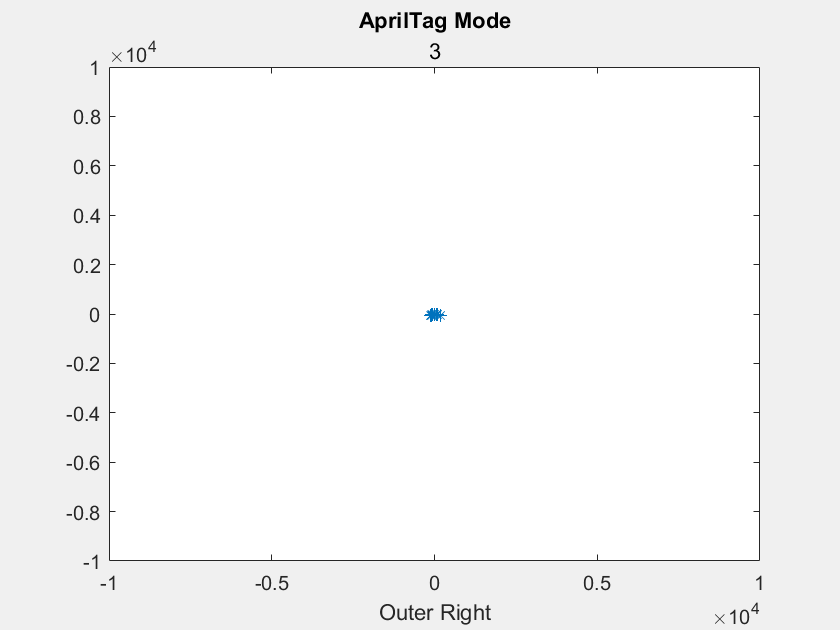

rpoints = 	1.0e+03 *

    3.2132   -1.0027
    5.4881    0.7032
    5.4837    0.7369
    5.4791    0.7706
    5.4347    0.7984
    5.3872    0.8253
    5.3138    0.8475
    5.2947    0.8778
    5.2814    0.9090
    5.2835    0.9428


slope = -1.6166

rpoints = 	1.0e+03 *

    5.5155   -0.2458
    5.5169   -0.2119
    5.5181   -0.1780
    5.4052    0.0913
    5.3876    0.1241
    5.4037    0.1577
    5.3856    0.1903
    5.3844    0.2234
    5.3959    0.2570
    5.4641    0.2939


slope = -2.1277

rpoints = 	1.0e+03 *

    3.0528   -0.9527
    3.0596   -0.9342
    3.0652   -0.9154
    5.3837   -1.0119
    5.3751   -0.9762
    5.3790   -0.9428
    5.3768   -0.9084
    5.3655   -0.8726
    5.3510   -0.8366
    5.3145   -0.7975


slope = -3.4993

rpoints = 	1.0e+03 *

    2.9048   -0.9065
    3.0070   -0.9181
    5.3379   -1.2085
    5.2778   -1.1609
    5.2497   -1.1209
    5.2496   -1.0872
    5.2434   -1.0524
    5.2361   -1.0175
    5.2422   -0.9853
    5.2482   -0.9531


slope = -2.0487

rpoints = 	1.0e+03 *

    4.7737   -0.9277
    4.7793   -0.8983
    4.7242   -0.4438
    4.7268   -0.4148
    4.6536   -0.1501
    4.6294   -0.1209
    4.6551   -0.0929
    4.6306   -0.0640
    4.6309   -0.0356
    4.6400   -0.0071


slope = -3.1561

rpoints = 	1.0e+03 *

    4.9534   -1.5458
    4.9628   -1.5153
    4.9720   -1.4848
    4.8668   -1.4209
    4.8755   -1.3910
    4.8627   -1.3551
    4.8507   -1.3197
    4.8587   -1.2899
    4.8665   -1.2600
    4.8257   -1.2179


slope = -4.4777

rpoints = 	1.0e+03 *

    3.4216   -0.9535
    3.4149   -0.9291
    3.3944   -0.9012
    3.3834   -0.8760
    3.3887   -0.8552
    3.3716   -0.8289
    3.3708   -0.8068
    3.3659   -0.7838
    3.3658   -0.7620
    3.3480   -0.7364


slope = -2.9720

rpoints = 	1.0e+03 *

    3.3273   -1.0160
    4.0590   -0.8928
    4.0644   -0.8678
    4.0696   -0.8428
    4.6385   -0.9310
    4.6490   -0.9034
    4.6751   -0.8787
    4.6952   -0.8527
    4.7191   -0.8271
    4.7241   -0.7981


slope = 1.1858

rpoints = 	1.0e+03 *

    4.5901   -1.2488
    4.5872   -1.1577
    4.5942   -1.1295
    4.4970   -1.0763
    4.4831   -1.0439
    4.4894   -1.0164
    4.5161   -0.9933
    4.5221   -0.9656
    4.4741   -0.9266
    4.4787   -0.8989


slope = 5.9747

rpoints = 	1.0e+03 *

    4.7937   -1.3677
    4.7567   -1.3256
    4.7648   -1.2963
    4.6961   -1.2159
    4.7607   -1.2015
    4.7751   -1.1429
    4.7821   -1.1136
    4.6856   -0.9404
    4.6912   -0.9116
    4.5975   -0.8641


slope = 9.8481

rpoints = 	1.0e+03 *

    4.4658   -1.2445
    4.4608   -1.2137
    4.4682   -1.1862
    4.4754   -1.1588
    4.4825   -1.1313
    4.4942   -1.1049
    4.5096   -1.0794
    4.5162   -1.0517
    4.5225   -1.0239
    4.5299   -0.9672


slope = 2.6490

rpoints = 	1.0e+03 *

    2.7693   -0.8642
    5.2131   -1.1802
    5.1978   -1.1432
    5.1920   -1.1086
    5.1987   -1.0767
    5.2052   -1.0447
    5.2115   -1.0127
    5.2176   -0.9807
    5.0514   -0.9174
    4.9880   -0.8742


slope = 11.6262

rpoints = 	1.0e+03 *

    4.5533   -1.2088
    4.5354   -1.1743
    4.5397   -1.1457
    4.4932   -1.1047
    4.4999   -1.0770
    4.4772   -1.0426
    4.4757   -1.0133
    4.4819   -0.9858
    4.4427   -0.9201
    4.3139   -0.7288


slope = 2.8116

rpoints = 	1.0e+03 *

    4.0992   -0.6409
    4.1031   -0.6157
    4.0929   -0.5885
    4.0964   -0.5633
    4.0998   -0.5382
    4.0683   -0.5086
    4.0714   -0.4836
    4.1507   -0.3899
    4.1441   -0.3636
    4.1462   -0.3382


slope = 4.2992

rpoints = 	1.0e+03 *

    4.1070   -0.0063
    4.0660    0.0187
    4.0658    0.0437
    4.0654    0.0687
    4.0649    0.0936
    4.1103    0.1199
    4.1274    0.1458
    4.1464    0.1720
    4.1453    0.1975
    4.1440    0.2229


slope = -1.3591

rpoints = 	1.0e+03 *

    4.7908   -1.3669
    4.7991   -1.3374
    4.9061   -1.3025
    4.9140   -1.2723
    4.9217   -1.2421
    4.8875   -1.2016
    4.8947   -1.1715
    4.8424   -1.1276
    4.8493   -1.0979
    4.8559   -1.0681


slope = 0.7781

rpoints = 	1.0e+03 *

    3.9110   -1.2205
    4.0878   -1.0317
    4.0941   -1.0065
    4.1002   -0.9814
    4.1061   -0.9562
    4.1688   -0.7571
    4.1665   -0.7303
    4.1709   -0.7047
    4.1821   -0.6802
    4.2296   -0.6613


slope = 4.0052

rpoints = 	1.0e+03 *

    4.2780   -1.1922
    4.2679   -1.1611
    4.2923   -1.1395
    4.2992   -1.1131
    4.3981   -1.1100
    4.4359   -1.0906
    4.4698   -1.0698
    4.4762   -1.0424
    4.4826   -1.0148
    4.4887   -0.9873


slope = 3.2523

rpoints = 	1.0e+03 *

    3.0985    0.1667
    3.0835    0.1849
    3.0683    0.2029
    3.0660    0.2217
    3.0646    0.2405
    3.0630    0.2593
    3.0793    0.2797
    3.0795    0.2988
    3.0916    0.3192
    3.1164    0.3411


slope = -4.1862

rpoints = 	1.0e+03 *

    3.0280   -0.9449
    3.0701   -0.9374
    3.0863   -0.9217
    3.0948   -0.9036
    3.1032   -0.8854
    3.1086   -0.8663
    3.1273   -0.8508
    3.1325   -0.8316
    3.1375   -0.8124
    3.1376   -0.7919


slope = 1.6439

rpoints = 	1.0e+03 *

    4.5737   -1.2746
    4.5890   -1.2183
    4.5567   -1.1798
    4.5658   -1.1523
    4.5728   -1.1242
    4.5777   -1.0957
    4.5843   -1.0675
    4.4982   -1.0184
    4.5034   -0.9905
    4.5094   -0.9628


slope = 5.4513

rpoints = 	1.0e+03 *

    4.5689   -1.2431
    4.5765   -1.2150
    4.6221   -1.1665
    4.8522   -1.1299
    4.8590   -1.1001
    4.9595   -1.0908
    4.8722   -1.0403
    4.8785   -1.0104
    4.7846   -0.9603
    4.7884   -0.9305


slope = -5.7846

rpoints = 	1.0e+03 *

    4.5602   -1.2708
    4.5680   -1.2428
    4.5755   -1.2147
    4.5829   -1.1866
    4.5862   -1.1574
    4.5932   -1.1293
    4.6001   -1.1010
    4.5678   -1.0637
    4.5742   -1.0356
    4.5991   -1.0116


slope = 2.9461

rpoints = 	1.0e+03 *

    2.9688   -0.9265
    5.4277   -1.2991
    5.3340   -1.2076
    5.3413   -1.1748
    5.3955   -1.1174
    5.4023   -1.0843
    5.4088   -1.0511
    5.3198   -0.9999
    5.3259   -0.9672
    5.3317   -0.9345


slope = -1.6549

rpoints = 	1.0e+03 *

    4.5383   -1.1751
    4.5416   -1.1462
    4.5524   -1.1192
    4.6040   -1.1019
    4.6106   -1.0737
    4.6172   -1.0453
    4.6450   -1.0217
    4.6844   -1.0002
    4.6572   -0.9645
    4.6493   -0.9332


slope = 5.1814

rpoints = 	1.0e+03 *

    4.6197   -1.3180
    4.6180   -1.2869
    4.6152   -1.2557
    4.6335   -1.2301
    4.6458   -1.2029
    4.6531   -1.1743
    4.6942   -1.1541
    4.7080   -1.1269
    4.7149   -1.0979
    4.7147   -1.0674


slope = 4.8298

rpoints = 	1.0e+03 *

    4.6519   -1.2656
    4.6744   -1.1797
    4.6097   -1.1333
    4.6156   -1.1047
    4.6223   -1.0764
    4.6298   -1.0482
    4.6860   -1.0307
    4.7099   -0.9153
    4.6974   -0.8233
    4.7246   -0.7386


slope = 5.1989

rpoints = 	1.0e+03 *

    4.8514   -1.3841
    4.8242   -1.3444
    4.7918   -1.3037
    4.7553   -1.2624
    4.7629   -1.2332
    4.7704   -1.2039
    4.7874   -1.1770
    4.8374   -1.1578
    4.8444   -1.1281
    4.8512   -1.0983


slope = 4.4837

rpoints = 	1.0e+03 *

    4.8486   -1.4156
    4.8379   -1.3803
    4.8463   -1.3506
    4.8545   -1.3208
    4.9032   -1.3017
    4.9120   -1.2718
    4.9197   -1.2416
    4.9263   -1.2111
    4.9288   -1.1797
    4.9359   -1.1494


slope = 4.5193

rpoints = 	1.0e+03 *

    4.9964   -1.4587
    4.9985   -1.4261
    4.9590   -1.3820
    4.9674   -1.3515
    4.9756   -1.3209
    5.1705   -1.3387
    5.1786   -1.3070
    5.1953   -1.2773
    5.1629   -1.2022
    5.0365   -1.1403


slope = 4.1619

rpoints = 	1.0e+03 *

    4.5698   -1.0051
    4.5866   -0.9793
    4.5925   -0.9511
    4.5983   -0.9229
    4.6667   -0.9069
    4.6722   -0.8782
    4.7326   -0.8595
    4.7378   -0.8304
    4.6876   -0.7920
    4.6144   -0.7505


slope = -5.5092

rpoints = 	1.0e+03 *

    4.6609   -0.8169
    4.6659   -0.7883
    4.5690   -0.7431
    4.5448   -0.7105
    4.5362   -0.6807
    4.5532   -0.6546
    4.5462   -0.6252
    4.5500   -0.5972
    4.5734   -0.5718
    4.5768   -0.5437


slope = 8.4361

rpoints = 	1.0e+03 *

    4.5269   -0.0348
    4.5270   -0.0070
    4.5270    0.0209
    4.5267    0.0487
    4.4744    0.0756
    3.4941    0.0805
    3.4705    0.1013
    3.4618    0.1223
    3.4570    0.1434
    3.4601    0.1648


slope = -10.5127

rpoints = 	1.0e+03 *

    3.4948   -0.6569
    3.4879   -0.6334
    3.4918   -0.6120
    3.4895   -0.5896
    3.4990   -0.5691
    3.5025   -0.5476
    3.4998   -0.5252
    3.5030   -0.5037
    3.4703   -0.4772
    3.4732   -0.4559


slope = 5.7126

rpoints = 	1.0e+03 *

    0.2816   -0.0879
    3.4086   -1.0408
    3.4293   -1.0241
    3.4528   -1.0081
    3.4542   -0.9855
    3.4602   -0.9643
    3.4959   -0.9511
    3.4717   -0.9217
    3.4773   -0.9003
    3.4750   -0.8770


slope = 3.2481

rpoints = 	1.0e+03 *

    4.8476   -1.1918
    4.8442   -1.1594
    4.8434   -1.1279
    4.8503   -1.0981
    4.8569   -1.0683
    4.8634   -1.0384
    4.8697   -1.0085
    4.8562   -0.9747
    4.8620   -0.9448
    4.8599   -0.9135


slope = 12.3793

rpoints = 	1.0e+03 *

    4.5443   -0.4551
    4.5470   -0.4271
    4.5495   -0.3992
    4.6167   -0.3765
    4.6189   -0.3482
    4.6209   -0.3198
    4.6228   -0.2914
    4.6245   -0.2630
    4.7031   -0.0939
    4.7036   -0.0650


slope = 4.6454

rpoints = 	1.0e+03 *

    4.9331   -1.4075
    4.9167   -1.3702
    4.8960   -1.3321
    4.8848   -1.2968
    4.8927   -1.2668
    4.9003   -1.2367
    4.8719   -1.1978
    4.8714   -1.1660
    4.8785   -1.1360
    4.8639   -1.1012


slope = 2.0521

rpoints = 	1.0e+03 *

    4.8111   -1.3089
    4.7688   -1.2660
    4.7542   -1.2310
    4.7588   -1.2010
    4.7690   -1.1725
    4.7761   -1.1432
    4.7801   -1.1131
    4.8103   -1.0890
    4.8169   -1.0595
    4.8213   -1.0294


slope = 4.5337

rpoints = 	1.0e+03 *

    4.9792   -1.5538
    5.0070   -1.4618
    4.9630   -1.4160
    4.9359   -1.3755
    4.9443   -1.3452
    4.9524   -1.3148
    4.9604   -1.2843
    4.9217   -1.2421
    4.9292   -1.2119
    4.9298   -1.1799


slope = 3.5800

rpoints = 	1.0e+03 *

    4.8447   -1.4145
    4.8274   -1.3773
    4.8328   -1.3468
    4.8304   -1.3142
    4.8229   -1.2804
    4.8094   -1.2452
    4.8141   -1.2149
    4.8107   -1.1827
    4.8160   -1.1527
    4.8230   -1.1231


slope = 4.6279

rpoints = 	1.0e+03 *

    4.5582   -0.5131
    4.5613   -0.4851
    4.5642   -0.4571
    4.6256   -0.4345
    4.6665   -0.3806
    4.6329   -0.3492
    4.6100   -0.3190
    4.6118   -0.2907
    4.6285   -0.2632
    4.6300   -0.2348


slope = -5.7448

rpoints = 	1.0e+03 *

    4.7910   -1.2405
    4.7617   -1.2017
    4.7525   -1.1684
    4.7596   -1.1392
    4.7830   -1.1138
    4.7898   -1.0844
    4.8120   -1.0584
    4.8741   -1.0407
    4.8804   -1.0108
    4.8758   -0.9786


slope = -4.3571

rpoints = 	1.0e+03 *

    4.5324    0.8088
    4.5216    0.8931
    4.5298    0.9236
    4.5397    0.9547
    4.5337    0.9826
    4.5237    1.0096
    4.5204    1.0380
    4.5149    1.0660
    4.5335    1.0998
    4.5267    1.1276


slope = 4.8952

rpoints = 	1.0e+03 *

    4.9293   -1.4064
    4.8675   -1.3565
    4.8719   -1.3255
    4.8800   -1.2955
    4.8617   -1.2588
    4.8461   -1.2230
    4.8535   -1.1932
    4.8588   -1.1629
    4.8551   -1.1306
    4.8307   -1.0937


slope = 4.8527

rpoints = 	1.0e+03 *

    5.0300   -1.4686
    5.0043   -1.4278
    5.0130   -1.3970
    5.0031   -1.3612
    4.9776   -1.3215
    4.9788   -1.2891
    4.9663   -1.2534
    4.9739   -1.2228
    5.0085   -1.1988
    5.0343   -1.1723


slope = -1.7785

rpoints = 	1.0e+03 *

    4.7002   -1.2788
    4.7079   -1.2499
    4.6948   -1.1848
    4.6981   -1.1550
    4.7051   -1.1262
    4.7090   -1.0966
    4.7157   -1.0676
    4.7221   -1.0386
    4.7235   -1.0086
    4.7365   -0.9810


slope = 9.1793

rpoints = 	1.0e+03 *

    4.5483   -0.5120
    4.5613   -0.4851
    4.5642   -0.4571
    4.5599   -0.4284
    4.5625   -0.4003
    4.5648   -0.3723
    4.5451   -0.3426
    4.5471   -0.3147
    4.6178   -0.2911
    4.6195   -0.2627


slope = 3.7143

rpoints = 	1.0e+03 *

    4.5571   -1.2098
    4.5645   -1.1818
    4.5952   -1.1297
    4.5806   -1.0964
    4.6087   -1.0732
    4.5937   -1.0400
    4.6000   -1.0118
    4.6062   -0.9835
    4.7083   -0.7955
    4.6894   -0.7627


slope = 4.1449

rpoints = 	1.0e+03 *

    4.7468   -1.3859
    4.7322   -1.3501
    4.7009   -1.3100
    4.6741   -1.2717
    4.6818   -1.2429
    4.7039   -1.2179
    4.7316   -1.1941
    4.7738   -1.1737
    4.7810   -1.1443
    4.7879   -1.1149


slope = 4.8032

rpoints = 72×2
	1.0e+03 *

    3.6460   -0.8727
    3.6513   -0.8503
    3.6565   -0.8278
    3.6615   -0.8053
    3.6664   -0.7828
    3.6740   -0.7609
    3.6786   -0.7383
    3.6743   -0.7140
    3.6658   -0.6890
    3.6631   -0.6652


slope = 3.0134

rpoints = 83×2
	1.0e+03 *

    3.5855   -1.1189
    3.6363   -1.1103
    3.6727   -1.0968
    3.6775   -1.0737
    3.6590   -1.0439
    3.6856   -1.0271
    3.6918   -1.0044
    3.6805   -0.9771
    3.6845   -0.9540
    3.6903   -0.9313


slope = 3.5249

rpoints = 83×2
	1.0e+03 *

    0.3933   -0.1227
    3.6018   -1.0998
    3.6344   -1.0854
    3.6899   -1.0773
    3.6965   -1.0546
    3.7029   -1.0319
    3.7092   -1.0091
    3.6989   -0.9820
    3.7048   -0.9592
    3.7436   -0.9448


slope = 2.3343

rpoints = 61×2
	1.0e+03 *

    4.7977    0.0516
    4.7973    0.0810
    4.7967    0.1105
    4.8140    0.1405
    4.8558    0.2014
    4.8545    0.2312
    4.8530    0.2611
    4.8513    0.2909
    4.8401    0.3798
    4.8716    0.4124


slope = 7.4711

rpoints = 85×2
	1.0e+03 *

    4.9206   -1.4366
    4.8793   -1.3921
    4.8675   -1.3565
    4.8661   -1.3239
    4.8316   -1.2827
    4.8336   -1.2515
    4.8412   -1.2218
    4.8486   -1.1920
    4.8831   -1.1688
    4.8980   -1.1406


slope = 4.0628

rpoints = 66×2
	1.0e+03 *

    5.2748   -1.5400
    5.2505   -1.4980
    5.2365   -1.4593
    5.2135   -1.4184
    5.2260   -1.3874
    5.2305   -1.3543
    5.2387   -1.3221
    5.2137   -1.2818
    5.2215   -1.2498
    5.1814   -1.2066


slope = 4.6548

rpoints = 50×2
	1.0e+03 *

    5.2434   -1.3920
    5.2334   -1.3550
    5.2029   -1.3131
    5.2108   -1.2811
    5.2186   -1.2491
    5.2301   -1.2179
    5.2375   -1.1857
    5.2446   -1.1536
    5.2252   -1.1157
    5.1938   -1.0757


slope = 7.0920

rpoints = 79×2
	1.0e+03 *

    5.2133   -1.5221
    5.2034   -1.4846
    5.1758   -1.4424
    5.1845   -1.4105
    5.1235   -1.3602
    5.0398   -1.3049
    5.1398   -1.2972
    5.1477   -1.2656
    5.1554   -1.2339
    5.1726   -1.2045


slope = 7.3690

rpoints = 94×2
	1.0e+03 *

    5.3317   -0.9345
    5.2299   -0.8836
    5.2352   -0.8514
    5.2374   -0.8188
    5.2453   -0.7871
    5.2470   -0.7544
    5.1753   -0.7117
    5.1637   -0.6778
    5.1360   -0.6421
    5.1011   -0.6059


slope = -2.7153

rpoints = 113×2
	1.0e+03 *

    5.2981   -1.4765
    5.2820   -1.4371
    5.2521   -1.3943
    5.1928   -1.3445
    5.2009   -1.3126
    5.2040   -1.2794
    5.1914   -1.2425
    4.0526   -0.9437
    4.0583   -0.9188
    4.0521   -0.8913


slope = -3.8352

rpoints = 99×2
	1.0e+03 *

    3.9813   -1.1095
    3.9736   -1.0811
    3.9647   -1.0525
    3.9420   -1.0207
    3.9472   -0.9962
    3.9465   -0.9702
    3.9349   -0.9418
    3.9581   -0.9217
    3.9705   -0.8989
    5.1885   -0.6811


slope = -4.1613

rpoints = 86×2
	1.0e+03 *

    5.3915   -1.0821
    5.3980   -1.0490
    5.4044   -1.0158
    5.4105   -0.9826
    5.4164   -0.9493
    5.3137   -0.8977
    5.3083   -0.8633
    5.3105   -0.8302
    5.3026   -0.7957
    5.2926   -0.7610


slope = -3.1817

rpoints = 62×2
	1.0e+03 *

    3.8694    1.4061
    3.8607    1.4299
    3.8640    1.4581
    3.8550    1.4818
    3.8458    1.5055
    3.8551    1.5365
    3.8484    1.5613
    3.8415    1.5860
    3.8317    1.6096
    3.8254    1.6346


slope = -1.6934

rpoints = 100×2
	1.0e+03 *

    5.3228   -1.5540
    5.3322   -1.5213
    5.2846   -1.4727
    5.2154   -1.4189
    5.2173   -1.3851
    5.1734   -1.3395
    5.1728   -1.3055
    5.1574   -1.2680
    5.0824   -1.2165
    5.0752   -1.1818


slope = -2.5679

rpoints = 62×2
	1.0e+03 *

    5.1989   -1.4488
    5.1595   -1.4037
    5.1371   -1.3638
    5.1424   -1.3315
    5.1505   -1.2999
    5.1613   -1.2689
    5.1739   -1.2384
    5.1814   -1.2066
    5.1887   -1.1747
    5.1870   -1.1409


slope = -2.3934

rpoints = 115×2
	1.0e+03 *

    4.3600   -1.2439
    4.3435   -1.2104
    4.3508   -1.1837
    4.3532   -1.1557
    4.2712   -1.1059
    4.3671   -1.1021
    4.2844   -1.0533
    4.2675   -1.0214
    4.2737   -0.9952
    4.2748   -0.9678


slope = -6.2048

rpoints = 119×2
	1.0e+03 *

    3.7247    0.3384
    3.6986    0.3589
    3.7202    0.3841
    3.7178    0.4069
    3.7152    0.4298
    3.7185    0.4533
    3.7156    0.4761
    3.6839    0.4951
    3.6600    0.5148
    3.6577    0.5374


slope = -5.6651

rpoints = 135×2
	1.0e+03 *

    4.0735   -1.1622
    4.0670   -1.1334
    4.0537   -1.1029
    4.0188   -1.0669
    4.0253   -1.0422
    4.0316   -1.0175
    4.0028   -0.9841
    4.0131   -0.8827
    4.0184   -0.8580
    3.9884   -0.8260


slope = -1.4266

rpoints = 117×2
	1.0e+03 *

    3.6741   -0.2090
    3.6593   -0.1856
    3.6764   -0.1638
    3.6613   -0.1406
    3.6621   -0.1181
    3.6608   -0.0956
    3.6613   -0.0731
    3.6287   -0.0501
    3.6189   -0.0278
    3.6190   -0.0056


slope = -0.8964

rpoints = 73×2
	1.0e+03 *

    3.6326    0.5565
    3.6094    0.5756
    3.5762    0.5929
    3.5725    0.6149
    3.5982    0.6421
    3.6148    0.6680
    3.6106    0.6901
    3.6152    0.7141
    3.6019    0.7344
    3.6042    0.7580


slope = 5.2789

rpoints = 119×2
	1.0e+03 *

    0.3112   -0.0971
    3.4852   -1.0642
    3.5721   -1.0668
    3.5834   -1.0462
    3.5955   -1.0258
    3.6114   -1.0064
    3.6667   -0.9976
    3.6824   -0.9776
    3.6990   -0.9577
    3.7048   -0.9350


slope = -2.0118

rpoints = 113×2
	1.0e+03 *

    0.4744   -0.1481
    3.7587   -1.1477
    3.8768   -1.1578
    3.9722   -1.1597
    3.9888   -1.1380
    4.0112   -1.1178
    4.0179   -1.0932
    4.0159   -1.0661
    4.0224   -1.0415
    4.0287   -1.0167


slope = -8.2210

rpoints = 81×2
	1.0e+03 *

    2.6219    0.0765
    2.6134    0.0923
    2.6128    0.1084
    2.6200    0.1248
    2.6202    0.1410
    2.6363    0.1581
    2.6352    0.1742
    2.6341    0.1904
    2.6389    0.2071
    2.6316    0.2228


slope = 1.2282

rpoints = 89×2
	1.0e+03 *

    2.6576   -0.5504
    2.6550   -0.5329
    2.6583   -0.5166
    2.6594   -0.4999
    2.6644   -0.4839
    2.6673   -0.4675
    2.6682   -0.4508
    2.6709   -0.4344
    2.6893   -0.4204
    2.6760   -0.4015


slope = 0.9522

rpoints = 68×2
	1.0e+03 *

    2.7025   -0.8433
    2.7095   -0.8273
    2.7145   -0.8107
    2.7175   -0.7934
    2.7070   -0.7723
    2.7117   -0.7557
    2.7114   -0.7377
    2.7092   -0.7192
    2.7135   -0.7026
    2.7052   -0.6827


slope = 1.2450

rpoints = 64×2
	1.0e+03 *

    3.9291   -1.2261
    4.0332   -1.2315
    4.0950   -1.0603
    4.0898   -1.0322
    4.0960   -1.0070
    4.1021   -0.9818
    4.1198   -0.9593
    4.0677   -0.8424
    4.0728   -0.8174
    4.0110   -0.7794


slope = 1.4320

rpoints = 68×2
	1.0e+03 *

    3.8365   -1.1973
    3.9347   -1.2014
    3.9525   -1.1804
    3.9597   -1.1561
    3.9667   -1.1317
    3.9736   -1.1073
    4.0025   -1.0890
    4.0178   -1.0667
    4.0243   -1.0420
    4.0471   -1.0214


slope = 1.6492

rpoints = 85×2
	1.0e+03 *

    5.2145   -1.1134
    5.2016   -1.0773
    5.1356   -1.0308
    5.0947   -0.9900
    5.1007   -0.9587
    5.1065   -0.9274
    5.1121   -0.8960
    5.0731   -0.8571
    5.0526   -0.8217
    5.0536   -0.7901


slope = 7.2842

rpoints = 93×2
	1.0e+03 *

    5.0330   -1.3693
    5.0336   -1.3363
    4.9992   -1.2944
    4.9711   -1.2546
    4.9525   -1.2176
    4.9560   -1.1862
    4.9632   -1.1558
    4.9546   -1.1217
    4.9770   -1.0947
    4.9837   -1.0641


slope = 6.8164

rpoints = 72×2
	1.0e+03 *

    5.0515   -0.9495
    4.9786   -0.9042
    4.9683   -0.8708
    4.9499   -0.8363
    4.9658   -0.8076
    4.9706   -0.7771
    4.9753   -0.7466
    4.9847   -0.7167
    4.9890   -0.6861
    4.9932   -0.6554


slope = 8.7685

rpoints = 97×2
	1.0e+03 *

    5.0398   -1.3712
    5.0085   -1.3297
    4.9953   -1.2934
    4.9847   -1.2580
    4.9826   -1.2250
    4.9998   -1.1967
    4.9798   -1.1596
    4.9868   -1.1290
    4.9936   -1.0984
    4.9856   -1.0645


slope = 5.1649

rpoints = 54×2
	1.0e+03 *

    4.8809    0.8709
    4.8951    0.9045
    4.8698    0.9308
    4.8621    0.9603
    4.8580    0.9906
    4.8714    1.0245
    4.8680    1.0551
    4.8819    1.0895
    4.8751    1.1195
    4.8682    1.1494


slope = -10.3496

rpoints = 75×2
	1.0e+03 *

    2.8877   -0.9011
    5.3528   -1.2465
    5.3603   -1.2136
    5.3413   -1.1748
    5.3748   -1.1476
    5.3558   -1.0408
    5.3287   -1.0016
    5.3347   -0.9688
    5.3386   -0.9357
    5.3462   -0.9032


slope = 14.3698

rpoints = 54×2
	1.0e+03 *

    4.8520    0.5311
    4.8487    0.5609
    4.8412    0.5901
    4.8374    0.6199
    4.8375    0.6501
    4.8295    0.6792
    4.8252    0.7089
    4.8030    0.7358
    4.7984    0.7653
    4.7936    0.7947


slope = -5.0229

rpoints = 100×2
	1.0e+03 *

    5.2216   -1.4898
    5.1257   -1.4284
    5.0195   -1.3657
    5.0240   -1.3338
    5.0243   -1.3009
    4.9828   -1.2575
    4.9904   -1.2269
    4.9978   -1.1962
    5.0051   -1.1655
    4.9819   -1.1279


slope = 7.0819

rpoints = 54×2
	1.0e+03 *

    4.8308   -0.2450
    4.8282   -0.2151
    4.8294   -0.1855
    4.8245   -0.1556
    4.8254   -0.1260
    4.8130   -0.0961
    4.8265   -0.0667
    4.8609   -0.0373
    4.8610   -0.0075
    4.8429    0.0223


slope = -7.0771

rpoints = 103×2
	1.0e+03 *

    5.1472   -1.6063
    5.1570   -1.5746
    5.1665   -1.5429
    5.1366   -1.4997
    5.0995   -1.4549
    5.0139   -1.3973
    5.0224   -1.3664
    5.0191   -1.3325
    5.0272   -1.3016
    5.0477   -1.2739


slope = 5.0180

rpoints = 105×2
	1.0e+03 *

    4.8758   -0.9475
    4.8452   -0.9107
    4.8507   -0.8809
    4.8629   -0.8523
    4.8522   -0.8198
    4.7960   -0.7800
    4.7948   -0.7496
    4.7943   -0.7194
    4.7987   -0.6899
    4.8078   -0.6611


slope = -6.4263

rpoints = 83×2
	1.0e+03 *

    4.8706   -0.4575
    4.7747   -0.4190
    4.7771   -0.3896
    4.7816   -0.3309
    4.7349   -0.2401
    3.8202   -0.1702
    3.8082   -0.1463
    3.8090   -0.1229
    3.8097   -0.0995
    3.8092   -0.0760


slope = -10.6262

rpoints = 86×2
	1.0e+03 *

    3.8024   -0.4991
    3.7994   -0.4750
    3.8013   -0.4515
    3.7990   -0.4276
    3.7956   -0.4036
    3.7940   -0.3799
    3.8003   -0.3570
    3.7984   -0.3333
    3.7904   -0.3091
    3.7922   -0.2859


slope = -2.9562

rpoints = 91×2
	1.0e+03 *

    3.8052   -1.0102
    3.7861   -0.9803
    3.7921   -0.9570
    3.7921   -0.9323
    3.7977   -0.9090
    3.7808   -0.8804
    3.7862   -0.8572
    3.7884   -0.8333
    3.7935   -0.8100
    3.7945   -0.7859


slope = 3.8319

rpoints = 84×2
	1.0e+03 *

    0.4401   -0.1373
    3.6353   -1.1100
    3.6813   -1.0994
    3.7264   -1.0880
    4.7323   -1.0104
    4.6944   -0.9722
    4.6885   -0.9410
    4.6844   -0.9103
    4.6899   -0.8815
    4.6932   -0.8523


slope = 5.9200

rpoints = 93×2
	1.0e+03 *

    4.8350   -1.5089
    4.8442   -1.4791
    4.8532   -1.4493
    4.8620   -1.4195
    4.8168   -1.3743
    4.8097   -1.3404
    4.7580   -1.2945
    4.7659   -1.2653
    4.7562   -1.2315
    4.7452   -1.1976


slope = 9.1023

rpoints = 57×2
	1.0e+03 *

    4.8428   -1.3817
    4.8492   -1.3514
    4.8439   -1.3179
    4.8519   -1.2881
    4.8597   -1.2583
    4.8024   -1.2120
    4.8098   -1.1825
    4.8169   -1.1529
    4.8308   -1.1249
    4.8571   -1.0996


slope = 3.1333

rpoints = 51×2
	1.0e+03 *

    5.1966   -1.4826
    5.1941   -1.4475
    5.1971   -1.4140
    5.1805   -1.3753
    5.1811   -1.3415
    5.1689   -1.3045
    5.1943   -1.2770
    5.2021   -1.2451
    5.1921   -1.2090
    5.2140   -1.1804


slope = 5.0595

rpoints = 65×2
	1.0e+03 *

    4.9387   -0.7411
    4.9432   -0.7107
    4.9702   -0.6835
    4.9515   -0.6499
    4.9782   -0.6224
    5.0207   -0.5964
    5.0243   -0.5655
    4.9740   -0.5290
    4.9771   -0.4984
    4.9801   -0.4678


slope = 5.7446

rpoints = 72×2
	1.0e+03 *

    5.1023   -1.5923
    5.1120   -1.5609
    5.1215   -1.5295
    4.9849   -1.4554
    4.9832   -1.4217
    4.9908   -1.3908
    4.9945   -1.3588
    4.9969   -1.3266
    5.0050   -1.2959
    5.0128   -1.2651


slope = 4.6702

rpoints = 133×2
	1.0e+03 *

    5.2952   -1.4757
    5.2801   -1.4365
    5.2434   -1.3920
    5.2160   -1.3505
    5.2242   -1.3185
    5.2613   -1.2935
    5.2400   -1.2542
    5.2573   -1.2242
    5.2648   -1.1919
    5.2280   -1.1499


slope = -5.9398

rpoints = 126×2
	1.0e+03 *

    5.2191   -1.5238
    5.1476   -1.4686
    5.1421   -1.4330
    5.0388   -1.3709
    5.0375   -1.3374
    5.0456   -1.3064
    5.0526   -1.2751
    5.0603   -1.2441
    5.0717   -1.2139
    5.0791   -1.1827


slope = -4.1321

rpoints = 79×2
	1.0e+03 *

    4.7733   -0.2127
    4.7745   -0.1834
    4.7775   -0.1541
    4.7784   -0.1248
    4.8400   -0.0966
    4.8405   -0.0669
    4.8439    0.0223
    4.8437    0.0521
    4.8433    0.0818
    4.8427    0.1116


slope = -4.3558

rpoints = 85×2
	1.0e+03 *

    4.8467   -0.7273
    4.8036   -0.6907
    4.7870   -0.6583
    4.7909   -0.6289
    4.7947   -0.5994
    4.8012   -0.5703
    4.8245   -0.5431
    4.8278   -0.5134
    4.8109   -0.4818
    4.8138   -0.4522


slope = 14.7502

rpoints = 116×2
	1.0e+03 *

    4.8995   -1.4304
    4.9081   -1.4003
    4.8540   -1.3527
    4.8565   -1.3213
    4.8645   -1.2914
    4.8026   -1.2435
    4.7879   -1.2083
    4.7952   -1.1789
    4.8024   -1.1494
    4.8093   -1.1199


slope = 11.8830

rpoints = 87×2
	1.0e+03 *

    5.1947   -1.4821
    5.2037   -1.4501
    5.2058   -1.4163
    5.1612   -1.3702
    5.1550   -1.3347
    5.1631   -1.3030
    5.1535   -1.2670
    5.0533   -1.2095
    5.0382   -1.1732
    5.0336   -1.1396


slope = 10.0789

rpoints = 113×2
	1.0e+03 *

    4.9372   -1.5407
    4.9735   -1.4190
    4.8540   -1.3527
    4.8555   -1.3210
    4.8191   -1.2794
    4.8268   -1.2498
    4.8344   -1.2201
    4.8360   -1.1889
    4.8490   -1.1606
    4.8502   -1.1294


slope = -3.6154

rpoints = 96×2
	1.0e+03 *

    5.1697   -1.4749
    5.1507   -1.4354
    5.1151   -1.3916
    5.0269   -1.3345
    4.9933   -1.2929
    5.0012   -1.2622
    5.0302   -1.2367
    5.0163   -1.2006
    5.0236   -1.1698
    5.0307   -1.1389


slope = 8.6290

rpoints = 106×2
	1.0e+03 *

    3.7523   -1.0705
    3.7588   -1.0475
    3.7545   -1.0215
    3.7569   -0.9974
    3.7629   -0.9743
    3.7640   -0.9499
    3.7552   -0.9232
    3.7588   -0.8997
    3.7643   -0.8766
    3.7491   -0.8488


slope = 8.4383

rpoints = 95×2
	1.0e+03 *

    0.3217   -0.1004
    3.5712   -1.0904
    3.8088   -1.1374
    5.1901   -1.2086
    5.0619   -1.1460
    5.0688   -1.1149
    5.0815   -1.0850
    5.0880   -1.0538
    5.0885   -1.0213
    5.0329   -0.9780


slope = -17.8011

rpoints = 52×2
	1.0e+03 *

    4.5501    0.7831
    4.5452    0.8110
    4.5457    0.8689
    4.5403    0.8968
    4.5376    0.9252
    4.5319    0.9531
    4.5259    0.9809
    4.5413    1.0135
    4.5135    1.0364
    4.5285    1.0692


slope = 3.2312

rpoints = 69×2
	1.0e+03 *

    4.5185   -0.2013
    4.5396   -0.1464
    4.5405   -0.1185
    4.5721   -0.0913
    4.5726   -0.0632
    4.5699   -0.0351
    4.5700   -0.0070
    4.5610    0.0210
    4.5607    0.0490
    4.5364    0.0766


slope = 3.3518

rpoints = 81×2
	1.0e+03 *

    4.7404   -1.3210
    4.7310   -1.2872
    4.7263   -1.2547
    4.7339   -1.2257
    4.7539   -1.1998
    4.7700   -1.1727
    4.7780   -1.1436
    4.8668   -1.1333
    4.8034   -1.0875
    4.8100   -1.0580


slope = 6.5286

rpoints = 93×2
	1.0e+03 *

    4.7442   -1.3221
    4.7281   -1.2864
    4.7069   -1.2496
    4.7145   -1.2207
    4.7219   -1.1917
    4.7564   -1.1694
    4.7635   -1.1401
    4.7704   -1.1108
    4.6913   -1.0621
    4.6870   -1.0309


slope = 5.8953

rpoints = 72×2
	1.0e+03 *

    5.1167   -1.5280
    5.0204   -1.4658
    5.0274   -1.4343
    4.9301   -1.3739
    4.9192   -1.3384
    4.9466   -1.3132
    4.9546   -1.2828
    4.9430   -1.2475
    4.8923   -1.2028
    4.9113   -1.1755


slope = 4.2770

rpoints = 70×2
	1.0e+03 *

    5.1807   -1.5126
    5.1764   -1.4769
    5.1064   -1.4230
    4.9925   -1.3583
    5.0008   -1.3276
    4.9962   -1.2936
    5.0167   -1.2661
    5.0273   -1.2360
    5.0698   -1.2134
    5.0772   -1.1823


slope = 3.6022

rpoints = 87×2
	1.0e+03 *

    5.0661   -1.5809
    4.8738   -1.3260
    4.8500   -1.2876
    4.8317   -1.2510
    4.8393   -1.2213
    4.8729   -1.1980
    4.9084   -1.1748
    4.9155   -1.1446
    4.9244   -1.1149
    4.9311   -1.0846


slope = 6.3483

rpoints = 84×2
	1.0e+03 *

    4.4939   -0.0345
    4.4940   -0.0069
    4.5607    0.0490
    4.5603    0.0770
    4.6936    0.2814
    4.6852    0.3966
    4.7036    0.4273
    4.7009    0.4562
    4.6682    0.4820
    4.6950    0.5139


slope = -1.1568

rpoints = 102×2
	1.0e+03 *

    4.7351   -1.3509
    4.7433   -1.3218
    4.6992   -1.2785
    4.7069   -1.2496
    4.6764   -1.1802
    4.6835   -1.1515
    4.6973   -1.1243
    4.6925   -1.0927
    4.7108   -1.0665
    4.7456   -1.0438


slope = 4.1325

rpoints = 100×2
	1.0e+03 *

    4.9928   -1.4245
    4.9244   -1.3723
    4.9327   -1.3420
    4.9592   -1.3166
    4.9672   -1.2861
    4.9333   -1.2450
    4.9409   -1.2147
    4.8947   -1.1715
    4.9019   -1.1415
    4.9068   -1.1109


slope = -1.9022

rpoints = 59×2
	1.0e+03 *

    4.3993    0.3724
    4.3969    0.3994
    4.4285    0.4572
    4.4256    0.4844
    4.4225    0.5116
    4.4193    0.5387
    4.4000    0.5638
    4.3965    0.5908
    4.3928    0.6178
    4.4265    0.6503


slope = 3.8056

rpoints = 82×2
	1.0e+03 *

    4.5064   -0.9333
    4.5101   -0.9052
    4.5175   -0.8779
    4.5279   -0.8223
    4.5387   -0.5674
    4.4696   -0.5309
    4.4628   -0.5023
    4.4658   -0.4749
    4.4786   -0.4485
    4.4952   -0.4223


slope = 6.2213

rpoints = 83×2
	1.0e+03 *

    5.1701   -1.6134
    5.1799   -1.5816
    5.1895   -1.5498
    4.9954   -1.4585
    4.9908   -1.4239
    4.9687   -1.3846
    4.9665   -1.3512
    4.9621   -1.3174
    4.9401   -1.2791
    4.9362   -1.2458


slope = 10.4810

rpoints = 77×2
	1.0e+03 *

    5.3386   -1.4877
    5.3476   -1.4549
    5.2269   -1.3877
    5.2325   -1.3548
    5.2436   -1.3233
    5.2487   -1.2904
    5.2536   -1.2574
    5.0275   -1.1707
    5.0346   -1.1398
    5.0415   -1.1089


slope = 8.5183

rpoints = 128×2
	1.0e+03 *

    4.5284   -1.2620
    4.5361   -1.2341
    4.5436   -1.2062
    4.5422   -1.1761
    4.5581   -1.1503
    4.5466   -1.1178
    4.5495   -1.0889
    4.5561   -1.0610
    4.5664   -1.0338
    4.5620   -1.0034


slope = 15.2351

rpoints = 130×2
	1.0e+03 *

    4.5216   -1.2302
    4.5291   -1.2024
    4.5086   -1.1379
    4.5223   -1.1118
    4.5356   -1.0562
    4.5421   -1.0283
    4.4741   -0.9553
    4.4799   -0.9278
    4.4855   -0.9003
    4.4910   -0.8727


slope = -11.8732

rpoints = 100×2
	1.0e+03 *

    5.1428   -1.4673
    5.0207   -1.3991
    5.0263   -1.3675
    4.9640   -1.3179
    4.9227   -1.2746
    4.9304   -1.2443
    4.9137   -1.2080
    4.8763   -1.1671
    3.5276   -0.8215
    3.4916   -0.7905


slope = -5.3410

rpoints = 112×2
	1.0e+03 *

    0.3055   -0.0953
    3.3847   -1.0335
    3.4408   -1.0276
    3.4557   -1.0089
    3.4628   -0.9880
    3.4679   -0.9664
    3.4650   -0.9427
    3.4572   -0.9178
    3.4435   -0.8916
    3.4460   -0.8697


slope = 3.0587

rpoints = 138×2
	1.0e+03 *

    4.5787   -1.1257
    4.5164   -1.0810
    4.5220   -1.0530
    4.5284   -1.0252
    4.5356   -0.9976
    4.5416   -0.9697
    4.4838   -0.9286
    4.4895   -0.9011
    4.4949   -0.8735
    4.5002   -0.8459


slope = -3.6845

rpoints = 70×2
	1.0e+03 *

    4.1281    0.8417
    4.1228    0.8671
    4.1174    0.8924
    4.1187    0.9192
    4.1169    0.9453
    4.1275    0.9745
    4.1215    0.9999
    4.1143    1.0249
    4.1079    1.0502
    4.1014    1.0754


slope = 6.4054

rpoints = 85×2
	1.0e+03 *

    4.5539   -1.3295
    4.5427   -1.2961
    4.5390   -1.2649
    4.5583   -1.2402
    4.5397   -1.2052
    4.5471   -1.1773
    4.5340   -1.1147
    4.4902   -1.0747
    4.4986   -1.0476
    4.5050   -1.0199


slope = 4.2874

rpoints = 98×2
	1.0e+03 *

    4.5959   -1.1599
    4.5942   -1.1295
    4.5553   -1.0903
    4.5619   -1.0623
    4.6142   -1.0447
    4.5766   -1.0066
    4.5827   -0.9785
    4.5886   -0.9503
    4.5463   -0.9125
    4.5519   -0.8845


slope = 3.8164

rpoints = 120×2
	1.0e+03 *

    4.1994   -1.1425
    4.1966   -1.1141
    4.2034   -1.0883
    4.2032   -1.0608
    4.2096   -1.0349
    4.2159   -1.0091
    4.1996   -0.9779
    4.2299   -0.9577
    4.2658   -0.9108
    4.2714   -0.8846


slope = 6.1717

rpoints = 88×2
	1.0e+03 *

    4.5834   -1.2773
    4.5892   -1.2486
    4.5794   -1.2157
    4.5867   -1.1876
    4.5940   -1.1594
    4.6709   -1.1484
    4.6779   -1.1196
    4.6847   -1.0909
    4.6577   -1.0245
    4.6639   -0.9958


slope = 4.3049

rpoints = 82×2
	1.0e+03 *

    5.0823   -1.5860
    5.1106   -1.4921
    4.9120   -1.4014
    4.8820   -1.3605
    4.8825   -1.3284
    4.8442   -1.2860
    4.8365   -1.2523
    4.8441   -1.2225
    4.8515   -1.1928
    4.8588   -1.1629


slope = 6.7090

rpoints = 112×2
	1.0e+03 *

    4.3225   -1.1192
    4.3293   -1.0926
    4.3359   -1.0660
    4.3326   -1.0370
    4.3487   -1.0126
    4.4114   -0.9987
    4.4762   -0.7280
    4.4697   -0.5867
    4.4732   -0.5592
    4.4765   -0.5317


slope = -1.7190

rpoints = 95×2
	1.0e+03 *

    4.5284   -1.2620
    4.5313   -1.2328
    4.5388   -1.2050
    4.5461   -1.1771
    4.5581   -1.1503
    4.5845   -1.1271
    4.5980   -1.0707
    4.6045   -1.0424
    4.5825   -1.0079
    4.5886   -0.9797


slope = 6.5751

rpoints = 127×2
	1.0e+03 *

    4.4687   -1.2453
    4.4580   -1.2129
    4.4441   -1.1798
    4.4212   -1.1447
    4.4282   -1.1176
    4.4349   -1.0903
    4.4415   -1.0631
    4.4529   -1.0369
    4.4611   -1.0100
    4.4653   -0.9821


slope = -1.3870

rpoints = 116×2
	1.0e+03 *

    4.8985   -1.3976
    4.8752   -1.3586
    4.8671   -1.3242
    4.8751   -1.2943
    4.8539   -1.2568
    4.8616   -1.2269
    4.8690   -1.1971
    4.8325   -1.1567
    4.8726   -1.1347
    4.8581   -1.0999


slope = -1.0726

rpoints = 93×2
	1.0e+03 *

    4.1909   -0.6026
    4.1282   -0.5677
    4.1316   -0.5423
    4.1348   -0.5169
    4.1588   -0.4940
    4.1617   -0.4685
    4.1725   -0.4437
    4.1781   -0.4184
    4.2224   -0.3966
    4.2387   -0.3719


slope = 3.2348

rpoints = 75×2
	1.0e+03 *

    4.3348   -1.2080
    4.3007   -1.1701
    4.3078   -1.1436
    4.3147   -1.1172
    4.3294   -0.9802
    4.3354   -0.9536
    4.3411   -0.9269
    4.3468   -0.9002
    4.3689   -0.8769
    4.3793   -0.8231


slope = -3.7802

rpoints = 52×2
	1.0e+03 *

    4.7500   -1.3237
    4.7571   -1.2942
    4.7649   -1.2650
    4.7707   -1.2352
    4.7811   -1.2066
    4.8117   -1.1830
    4.8189   -1.1534
    4.8249   -1.1235
    4.8317   -1.0939
    4.8383   -1.0642


slope = 4.7473

rpoints = 103×2
	1.0e+03 *

    3.9638   -0.3478
    3.9290   -0.3204
    3.9199   -0.2955
    3.9266   -0.2717
    3.9282   -0.2476
    3.9296   -0.2235
    3.9280   -0.1992
    3.9291   -0.1751
    3.9281   -0.1509
    3.8930   -0.1256


slope = -10.6245

rpoints = 54×2
	1.0e+03 *

    4.6344   -1.2915
    4.6423   -1.2630
    4.6499   -1.2345
    4.6574   -1.2059
    4.6508   -1.0230
    4.6570   -0.9944
    4.6630   -0.9657
    4.6689   -0.9371
    4.6746   -0.9084
    4.6712   -0.8780


slope = -7.6249

rpoints = 143×2
	1.0e+03 *

    3.9207   -1.0151
    3.9269   -0.9910
    3.9388   -0.9427
    3.9396   -0.9174
    2.9416   -0.6660
    2.9358   -0.6457
    2.9329   -0.6262
    2.9230   -0.6054
    2.9266   -0.5874
    2.9282   -0.5690


slope = -3.1926

rpoints = 123×2
	1.0e+03 *

    2.9325   -0.9151
    2.9381   -0.8971
    2.9435   -0.8791
    2.9450   -0.8598
    2.9339   -0.8371
    2.9342   -0.8177
    2.9170   -0.7936
    2.9102   -0.7726
    2.9100   -0.7535
    2.9146   -0.7356


slope = 0.0770

rpoints = 103×2
	1.0e+03 *

    0.3150   -0.0983
    4.0800   -1.2458
    4.0876   -1.2207
    4.1148   -1.1740
    4.1219   -1.1487
    4.1377   -1.0985
    4.1424   -1.0725
    4.1353   -1.0437
    4.1417   -1.0182
    4.1547   -0.9944


slope = 6.7626

rpoints = 57×2
	1.0e+03 *

    4.5998   -1.2515
    4.5871   -1.2178
    4.6148   -1.1949
    4.5910   -1.1587
    4.6292   -1.1381
    4.6681   -1.1173
    4.6749   -1.0886
    4.6181   -1.0455
    4.5121   -0.9924
    4.5182   -0.9647


slope = 8.0146

rpoints = 119×2
	1.0e+03 *

    3.8854   -1.0315
    3.8907   -1.0074
    3.8920   -0.9822
    3.8979   -0.9583
    3.9086   -0.9355
    3.9143   -0.9115
    3.8964   -0.8821
    3.8900   -0.8556
    3.8864   -0.8298
    3.8571   -0.7988


slope = 3.2338

rpoints = 101×2
	1.0e+03 *

    0.4229   -0.1320
    4.1667   -1.1062
    4.1734   -1.0806
    4.1644   -1.0510
    4.1630   -1.0235
    4.1770   -0.9998
    4.0818   -0.9505
    4.0876   -0.9254
    4.1244   -0.9072
    4.1299   -0.8818


slope = 2.7398

rpoints = 102×2
	1.0e+03 *

    4.0629   -1.1592
    4.0699   -1.1342
    4.0768   -1.1092
    4.0574   -1.0772
    4.0369   -1.0452
    4.0258   -1.0160
    4.0213   -0.9886
    4.0253   -0.9634
    4.0331   -0.9392
    4.0495   -0.9168


slope = 3.1636

rpoints = 76×2
	1.0e+03 *

    3.7802   -1.1797
    3.8629   -1.1795
    3.8701   -1.1558
    3.8771   -1.1320
    3.8840   -1.1081
    3.9495   -1.1006
    3.9562   -1.0764
    3.9627   -1.0520
    3.9498   -1.0227
    3.9560   -0.9984


slope = 1.6285

rpoints = 61×2
	1.0e+03 *

    4.4543   -1.2413
    4.4618   -1.2139
    4.4808   -1.1896
    4.4880   -1.1620
    4.5048   -1.1369
    4.5320   -1.1142
    4.5883   -0.7173
    4.5926   -0.6891
    4.6927   -0.6747
    4.6968   -0.6459


slope = 2.4171

rpoints = 62×2
	1.0e+03 *

    4.4035   -1.1690
    4.4096   -1.1417
    4.3826   -1.1061
    4.3893   -1.0791
    4.4007   -1.0533
    4.4071   -1.0263
    4.4338   -1.0038
    4.4535   -0.9796
    4.4624   -0.9528
    4.5289   -0.9380


slope = 1.8137

rpoints = 54×2
	1.0e+03 *

    5.4674    0.4628
    5.4296    0.4932
    5.4235    0.5263
    5.4013    0.5576
    5.3978    0.5908
    5.3136    0.6146
    5.2799    0.6436
    5.2759    0.6760
    5.2706    0.7083
    5.2662    0.7407


slope = -1.0137

rpoints = 76×2
	1.0e+03 *

    3.2566   -0.9944
    3.2904   -0.9826
    5.3949   -0.6073
    5.3568   -0.5697
    5.3453   -0.5353
    5.3485   -0.5024
    5.3494   -0.4694
    5.3293   -0.4347
    5.3169   -0.4008
    5.2175   -0.3611


slope = -2.8033

rpoints = 65×2
	1.0e+03 *

    3.0729   -0.9589
    3.1456   -0.9605
    5.3817   -0.9092
    5.3655   -0.8726
    5.3688   -0.8393
    5.3758   -0.8067
    5.3510   -0.7694
    5.3556   -0.7365
    5.3184   -0.6981
    5.2620   -0.6579


slope = 11.3400

rpoints = 77×2
	1.0e+03 *

    5.1178   -1.4601
    5.0342   -1.4029
    5.0359   -1.3701
    4.9814   -1.3225
    4.9885   -1.2916
    4.9459   -1.2482
    4.8981   -1.2042
    4.9054   -1.1741
    4.9126   -1.1440
    4.9205   -1.1140


slope = 3.8187

rpoints = 58×2
	1.0e+03 *

    2.8142   -0.8782
    5.1885   -1.5843
    5.2135   -1.5569
    5.2229   -1.5249
    5.2168   -1.4884
    5.1883   -1.4459
    5.1971   -1.4140
    5.2057   -1.3820
    5.1492   -1.3332
    5.2252   -1.3187


slope = 5.4653

rpoints = 76×2
	1.0e+03 *

    5.0890   -1.5881
    5.0986   -1.5568
    5.1081   -1.5255
    5.0905   -1.4862
    5.0091   -1.4291
    4.9831   -1.3887
    4.9771   -1.3541
    4.9814   -1.3225
    4.9546   -1.2828
    4.9624   -1.2524


slope = 5.7092

rpoints = 53×2
	1.0e+03 *

    5.1193   -1.4946
    5.1284   -1.4632
    5.1373   -1.4316
    5.1768   -1.4084
    5.2105   -1.3833
    5.2266   -1.3533
    5.2349   -1.3211
    5.2691   -1.2954
    5.2770   -1.2630
    5.2116   -1.2136


slope = 5.9395

rpoints = 67×2
	1.0e+03 *

    3.5469   -1.0356
    3.5455   -1.0116
    3.5372   -0.9857
    3.5577   -0.9679
    3.5636   -0.9461
    3.5635   -0.9227
    3.5545   -0.8971
    3.5600   -0.8752
    3.5439   -0.8482
    3.5490   -0.8264


slope = 2.4467

rpoints = 52×2
	1.0e+03 *

    0.3284   -0.1025
    3.4976   -1.0680
    3.5156   -1.0499
    3.5421   -1.0342
    3.5676   -1.0179
    3.5767   -0.9967
    3.5828   -0.9748
    3.5800   -0.9504
    3.5858   -0.9284
    3.5875   -0.9054


slope = 0.6778

rpoints = 62×2
	1.0e+03 *

    5.2627   -1.4318
    5.2405   -1.3913
    5.2073   -1.3483
    5.2155   -1.3163
    5.2147   -1.2820
    5.2225   -1.2500
    5.2301   -1.2179
    5.2375   -1.1857
    5.2446   -1.1536
    5.2898   -1.1295


slope = 2.6121

rpoints = 68×2
	1.0e+03 *

    5.5490   -0.3156
    5.4650   -0.2772
    5.4666   -0.2436
    5.4670   -0.2100
    5.4292   -0.1751
    5.4272   -0.1417
    5.4279   -0.1084
    5.4285   -0.0750
    5.4258   -0.0417
    5.4160   -0.0083


slope = -2.8159

rpoints = 59×2
	1.0e+03 *

    5.3784   -0.7396
    5.3828   -0.7066
    5.3871   -0.6735
    5.3951   -0.6409
    5.4416   -0.6125
    5.4453   -0.5791
    5.4060   -0.5413
    5.4112   -0.5083
    5.3953   -0.4734
    5.3881   -0.4395


slope = -2.4613

rpoints = 73×2
	1.0e+03 *

    5.4394   -1.1614
    5.4464   -1.1280
    5.3660   -1.0770
    5.3332   -1.0364
    3.7513   -0.7051
    3.7418   -0.6795
    3.7104   -0.6503
    3.7124   -0.6272
    3.7043   -0.6025
    3.6912   -0.5771


slope = -2.8743

rpoints = 56×2
	1.0e+03 *

    0.3627   -0.1132
    3.4708   -1.0598
    3.5156   -1.0499
    3.6007   -1.0513
    3.6109   -1.0302
    3.6172   -1.0080
    3.6291   -0.9874
    3.6351   -0.9650
    3.6313   -0.9402
    3.6244   -0.9147


slope = -0.0211

rpoints = 96×2
	1.0e+03 *

    4.8385   -1.1267
    4.8337   -1.0943
    4.7856   -1.0526
    4.7900   -1.0228
    4.7962   -0.9933
    4.8042   -0.9642
    4.8228   -0.9372
    4.8628   -0.9140
    4.8392   -0.8482
    4.8443   -0.8184


slope = 0.0431

rpoints = 93×2
	1.0e+03 *

    4.5882   -1.2786
    4.5959   -1.2504
    4.5948   -1.2198
    4.5722   -1.1838
    4.6095   -1.1633
    4.6194   -1.1357
    4.6263   -1.1073
    4.6350   -1.0793
    4.6883   -1.0614
    4.7172   -1.0376


slope = 4.1455

rpoints = 50×2
	1.0e+03 *

    5.3303   -1.3105
    5.3382   -1.2777
    5.3460   -1.2449
    5.3321   -1.2072
    5.3394   -1.1744
    5.3729   -1.1472
    5.3495   -1.1079
    5.3562   -1.0750
    5.3627   -1.0421
    5.2874   -0.9938


slope = -0.1075

rpoints = 116×2
	1.0e+03 *

    4.6562   -1.3284
    4.6585   -1.2982
    4.6259   -1.2585
    4.6335   -1.2301
    4.6410   -1.2016
    4.6007   -1.1611
    4.6058   -1.1324
    4.6127   -1.1040
    4.6720   -1.0879
    4.6786   -1.0592


slope = -0.0514

rpoints = 76×2
	1.0e+03 *

    4.7610   -1.3583
    4.7490   -1.3234
    4.7542   -1.2935
    4.7620   -1.2642
    4.7184   -1.2217
    4.7258   -1.1927
    4.7136   -1.1589
    4.7061   -1.1264
    4.7275   -1.1009
    4.7615   -1.0780


slope = -0.0702

rpoints = 98×2
	1.0e+03 *

    4.4183   -1.1440
    4.4165   -1.1146
    4.4233   -1.0875
    4.4007   -1.0533
    4.4071   -1.0263
    4.4192   -1.0005
    4.4252   -0.9733
    4.4790   -0.9276
    4.4659   -0.8964
    4.4714   -0.8689


slope = -0.0280

rpoints = 69×2
	1.0e+03 *

    4.5988   -1.2816
    4.6017   -1.2520
    4.6093   -1.2237
    4.6003   -1.1911
    4.5959   -1.1599
    4.6029   -1.1316
    4.6098   -1.1033
    4.6165   -1.0750
    4.6211   -1.0462
    4.6342   -1.0193


slope = 1.2035

rpoints = 77×2
	1.0e+03 *

    4.4154   -1.1432
    4.4223   -1.1161
    4.4291   -1.0889
    4.4989   -1.0768
    4.5055   -1.0492
    4.5128   -1.0217
    4.4331   -0.8615
    4.2879   -0.8060
    4.2642   -0.7744
    4.2689   -0.7482


slope = 2.9234

rpoints = 64×2
	1.0e+03 *

    3.2820   -0.9364
    3.2694   -0.9111
    3.2750   -0.8910
    3.2726   -0.8688
    3.2779   -0.8487
    3.2772   -0.8271
    3.2813   -0.8067
    3.2823   -0.7856
    3.2871   -0.7654
    3.2917   -0.7452


slope = 8.6105

rpoints = 71×2
	1.0e+03 *

    0.4067   -0.1269
    3.8916   -1.1883
    3.9165   -1.1435
    3.9234   -1.1194
    3.9302   -1.0953
    3.9369   -1.0711
    3.9202   -1.0407
    3.9226   -1.0156
    3.9026   -0.9849
    3.9086   -0.9609


slope = 0.3743

rpoints = 54×2
	1.0e+03 *

    4.2227   -1.2329
    4.2235   -1.2050
    4.2308   -1.1790
    4.2447   -1.1548
    4.3339   -1.1506
    4.3651   -1.1302
    4.4349   -1.1193
    4.5194   -1.1111
    4.7579    1.0006
    4.6823    1.0148


slope = 6.8060

rpoints = 55×2
	1.0e+03 *

    4.8783   -1.3918
    4.8868   -1.3618
    4.8951   -1.3318
    4.9254   -1.3076
    4.9546   -1.2828
    4.9721   -1.2548
    5.0419   -1.2395
    5.0504   -1.2088
    5.0616   -1.1787
    5.0951   -1.1535


slope = 1.3377

rpoints = 64×2
	1.0e+03 *

    5.1826   -1.5131
    5.0091   -1.4291
    5.0178   -1.3983
    5.0263   -1.3675
    5.0346   -1.3366
    5.0679   -1.3122
    5.1641   -1.3033
    5.1720   -1.2715
    5.1797   -1.2398
    5.2330   -1.2186


slope = 2.3923

rpoints = 77×2
	1.0e+03 *

    5.1468    0.3086
    5.1448    0.3402
    5.1426    0.3718
    5.1581    0.4048
    5.1695    0.4376
    5.1727    0.4699
    5.1697    0.5017
    5.1466    0.5313
    5.1343    0.5620
    5.1278    0.5931


slope = -1.7383

rpoints = 81×2
	1.0e+03 *

    2.9488   -0.9202
    3.0242   -0.9234
    3.0582   -0.3823
    3.0605   -0.3635
    3.0627   -0.3447
    3.0647   -0.3259
    3.0667   -0.3071
    3.0565   -0.2871
    3.0553   -0.2681
    3.0329   -0.2474


slope = -1.8416

rpoints = 79×2
	1.0e+03 *

    5.1536   -1.4362
    5.0138   -1.3641
    5.0085   -1.3297
    4.9924   -1.2926
    5.0002   -1.2619
    4.9943   -1.2279
    4.9599   -1.1871
    3.0611   -0.7128
    3.0586   -0.6925
    3.0618   -0.6734


slope = 0.1938

rpoints = 98×2
	1.0e+03 *

    3.0328   -0.9464
    3.0385   -0.9278
    3.0442   -0.9091
    3.0238   -0.8828
    3.0272   -0.8637
    2.9843   -0.8316
    2.9893   -0.8133
    2.9943   -0.7949
    3.0233   -0.7828
    3.0862   -0.7789


slope = 0.2131

rpoints = 56×2
	1.0e+03 *

    3.6076   -1.1015
    3.6459   -1.0888
    4.7201   -1.3154
    4.8285   -1.3137
    4.8443   -1.2543
    4.8519   -1.2245
    4.5869   -1.0385
    4.5747   -1.0062
    4.5592   -0.9735
    4.5651   -0.9455


slope = 3.2043

rpoints = 102×2
	1.0e+03 *

    4.2197   -1.0649
    4.2262   -1.0390
    4.2318   -0.9854
    4.2378   -0.9594
    4.2104   -0.9261
    4.1827   -0.8931
    4.1881   -0.8674
    4.1914   -0.8413
    4.1965   -0.8155
    4.2545   -0.7997


slope = 1.5419

rpoints = 93×2
	1.0e+03 *

    4.4473   -1.2100
    4.4547   -1.1826
    4.4619   -1.1553
    4.4689   -1.1278
    4.4417   -1.0920
    4.3929   -1.0514
    4.3993   -1.0244
    4.4104   -0.9985
    4.4018   -0.9682
    4.3940   -0.9382


slope = 3.8965

rpoints = 81×2
	1.0e+03 *

    4.3692   -1.1887
    4.3757   -1.1329
    4.3797   -1.1053
    4.3893   -1.0791
    4.3958   -1.0521
    4.3993   -1.0244
    4.3753   -0.9906
    4.3813   -0.9637
    4.3871   -0.9367
    4.3820   -0.9075


slope = 4.3151

rpoints = 68×2
	1.0e+03 *

    4.3025   -1.0298
    4.3087   -1.0033
    4.2904   -0.9713
    4.2963   -0.9450
    4.3265   -0.9238
    4.3091   -0.8649
    4.3056   -0.7819
    4.3103   -0.7555
    4.3676   -0.7103
    4.3807   -0.4115


slope = 0.2688

rpoints = 87×2
	1.0e+03 *

    4.5230   -1.0532
    4.5294   -1.0254
    4.6375   -0.9902
    4.5779   -0.9481
    4.6052   -0.9243
    4.5892   -0.8918
    4.5818   -0.8612
    4.5515   -0.8266
    4.5565   -0.7986
    4.5614   -0.7706


slope = 0.0512

rpoints = 92×2
	1.0e+03 *

    4.7812   -1.3008
    4.7891   -1.2714
    4.7959   -1.2417
    4.8044   -1.2125
    4.8249   -1.1235
    4.7001   -1.0641
    4.7065   -1.0352
    4.7128   -1.0063
    4.7267   -0.9789
    4.8022   -0.9638


slope = 0.2985

rpoints = 159×2
	1.0e+03 *

    4.2963   -1.1124
    4.1751   -1.0537
    4.1815   -1.0280
    4.1877   -1.0023
    4.1198   -0.9593
    4.0651   -0.9203
    3.9994   -0.8797
    4.0047   -0.8551
    4.0099   -0.8305
    4.0110   -0.8050


slope = 0.3701

rpoints = 247×2
	1.0e+03 *

    3.4547   -1.0781
    3.5502   -1.0840
    3.7216   -1.1114
    3.7283   -1.0885
    3.7657   -1.0744
    3.8127   -1.0625
    3.8356   -1.0435
    3.8419   -1.0200
    3.8316   -0.9921
    3.8377   -0.9685


slope = 0.4753

rpoints = 278×2
	1.0e+03 *

    0.3647   -0.1138
    3.6191   -1.1050
    3.7120   -1.1085
    3.7946   -1.1079
    3.8143   -1.0378
    3.7453   -0.9943
    3.7406   -0.9685
    3.7368   -0.9431
    3.7426   -0.9201
    3.7481   -0.8971


slope = -1.4919

rpoints = 184×2
	1.0e+03 *

    2.6993    0.5850
    2.6889    0.6001
    2.6705    0.6132
    2.6005    0.6140
    2.5811    0.6262
    2.5394    0.6326
    2.4686    0.6311
    2.4550    0.6437
    2.3805    0.6398
    2.3457    0.6459


slope = 0.5367

rpoints = 224×2
	1.0e+03 *

    2.9128   -0.8310
    2.9005   -0.8083
    2.9054   -0.7905
    2.9276   -0.7772
    2.9430   -0.7620
    2.9641   -0.7481
    2.9890   -0.7348
    2.9964   -0.7172
    3.0144   -0.7019
    3.0264   -0.6852


slope = 0.4063

rpoints = 206×2
	1.0e+03 *

    2.7961   -0.7423
    2.8006   -0.7251
    2.8050   -0.7079
    2.8132   -0.6916
    2.8408   -0.6799
    2.8449   -0.6625
    2.8255   -0.6397
    2.6233   -0.5770
    2.5838   -0.5517
    2.5107   -0.5200


slope = 0.2960

rpoints = 172×2
	1.0e+03 *

    2.7206   -0.8490
    2.7258   -0.8323
    2.7308   -0.8155
    2.6820   -0.7830
    2.6849   -0.7660
    2.6491   -0.7382
    2.6391   -0.7180
    2.6434   -0.7018
    2.6477   -0.6855
    2.6344   -0.6649


slope = -4.9982

rpoints = 183×2
	1.0e+03 *

    2.3139   -0.7221
    2.3269   -0.7105
    2.3313   -0.6962
    2.3269   -0.6793
    2.2877   -0.6527
    2.2705   -0.6327
    2.2386   -0.6091
    2.2423   -0.5953
    2.2256   -0.5763
    2.2291   -0.5626


slope = -2.7069

rpoints = 133×2
	1.0e+03 *

    1.0737   -0.3423
    1.0949   -0.3417
    1.1152   -0.3405
    1.1115   -0.3319
    1.1193   -0.3268
    1.1270   -0.3215
    1.1290   -0.3146
    1.1251   -0.3061
    1.1347   -0.3012
    1.1297   -0.2925


slope = 3.9525

rpoints = 78×2
	1.0e+03 *

    2.9631   -0.9247
    2.9763   -0.9088
    2.9819   -0.8905
    2.9873   -0.8722
    2.9320   -0.8365
    2.9371   -0.8185
    2.9421   -0.8004
    2.9682   -0.7880
    3.0523   -0.7903
    3.1027   -0.7830


slope = 0.9739

rpoints = 53×2
	1.0e+03 *

    3.1063   -0.9694
    3.1533   -0.9628
    3.1821   -0.9503
    3.1879   -0.9307
    3.1705   -0.9046
    3.1760   -0.8851
    3.1678   -0.8619
    3.1731   -0.8424
    3.1840   -0.8244
    3.1890   -0.8048


slope = 1.6308

rpoints = 50×2
  679.8881   91.3682
  667.4311   93.8710
  655.9588   96.3696
  647.4468   99.1852
  642.8753  102.5299
  637.3008  105.6586
  636.6398  109.5709
  633.0015  112.9520
  629.3457  116.2925
  624.6907  119.4047


slope = -1.1892

rpoints = 51×2
  647.0949 -129.8776
  639.0457 -124.1839
  635.8652 -119.5178
  628.7160 -114.1806
  627.4354 -109.9717
  615.2807 -103.9503
  613.9335  -99.8483
  599.7152  -93.7588
  600.2797  -90.0737
  600.8216  -86.3851


slope = 0.9144

rpoints = 70×2
	1.0e+03 *

    1.9206    3.1132
    1.8999    3.1224
    1.8771    3.1280
    1.8579    3.1395
    1.8385    3.1508
    1.7608    3.0606
    1.7420    3.0714
    1.6943    3.0305
    1.6737    3.0374
    1.6345    3.0098


slope = 0.3305

rpoints = 106×2
	1.0e+03 *

    3.2808    3.2358
    3.2573    3.2523
    3.1880    3.2225
    3.1011    3.1734
    3.0815    3.1923
    3.0598    3.2090
    3.0400    3.2278
    2.6174    3.0300
    2.5988    3.0461
    2.5581    3.0360


slope = 0.3468

rpoints = 96×2
	1.0e+03 *

    2.5549    3.0321
    2.5228    3.0316
    2.4743    3.0108
    2.4557    3.0259
    2.4252    3.0261
    2.3389    2.9555
    2.3158    2.9635
    2.2811    2.9563
    2.2629    2.9702
    2.1947    2.9177


slope = 0.4094

rpoints = 52×2
	1.0e+03 *

    1.9195    2.8691
    1.9018    2.8809
    1.2124    2.5605
    1.1966    2.5679
    1.1020    2.5250
    1.0458    2.4371
    0.9830    2.3301
    0.9679    2.3343
    0.9472    2.3244
    0.9243    2.3089


slope = 0.5286

rpoints = 96×2
	1.0e+03 *

    3.9999    3.2360
    3.9800    3.2605
    3.9599    3.2849
    3.9434    3.3124
    3.9314    3.3437
    3.9206    3.3762
    3.9164    3.4147
    3.9246    3.4645
    3.9123    3.8115
    3.8888    3.8354


slope = 0.1989

rpoints = 76×2
	1.0e+03 *

    4.0992    2.8067
    4.0704    2.8238
    4.0530    2.8488
    4.0468    2.8817
    4.0363    2.9118
    4.0684    2.9731
    1.8813    3.1791
    1.8617    3.1906
    1.8421    3.2019
    1.8224    3.2132


slope = -0.6822

rpoints = 124×2
	1.0e+03 *

    4.2970    2.1571
    4.2836    2.1834
    4.2497    2.1991
    4.2361    2.2252
    4.2461    2.3313
    4.1694    2.5282
    4.1520    2.5527
    4.1363    2.5782
    4.1221    2.6046
    4.1355    2.6487


slope = -1.4653

rpoints = 163×2
	1.0e+03 *

    4.5626    1.0772
    4.5559    1.1052
    4.5490    1.1332
    4.5419    1.1611
    4.5347    1.1890
    4.5351    1.2189
    4.5178    1.2441
    4.5197    1.2745
    4.5041    1.3000
    4.5248    1.3362


slope = -1.2269

rpoints = 106×2
  545.8081   36.0898
  539.5918   39.0088
  538.3451   42.2439
  528.1111   44.7061
  527.8266   47.9488
  523.5408   50.8034
  523.2189   54.0180
  522.8773   57.2305
  522.5159   60.4409
  525.1128   64.0120


slope = -2.0380

rpoints = 55×2
  344.5246   76.8882
  341.1220   78.3314
  338.6880   79.9654
  330.4159   80.1580
  329.9174   82.1859
  328.4375   83.9630
  320.1772   83.9496
  319.6556   85.9145
  319.1219   87.8762
  315.6887   89.0203


slope = -0.8961

rpoints = 197×2
  339.8368 -106.0516
  340.4818 -103.9623
  342.0720 -102.1553
  342.6930 -100.0524
  343.3011  -97.9458
  341.9696  -95.2985
  340.6186  -92.6713
  334.4157  -88.7814
  333.9866  -86.4751
  335.4810  -84.6669


slope = -0.0437

rpoints = 252×2
  343.6552 -107.2432
  348.1330 -106.2986
  354.5285 -105.8753
  355.1720 -103.6958
  354.8406 -101.2381
  355.4557  -99.0568
  356.0574  -96.8717
  356.6457  -94.6830
  362.0608  -93.7440
  362.6298  -91.5185


slope = -0.3425

rpoints = 241×2
	1.0e+03 *

    0.2544   -0.0811
    0.3809   -0.1189
    0.3873   -0.1183
    0.4034   -0.1205
    0.4060   -0.1185
    0.4145   -0.1182
    4.7319   -1.0408
    4.7343   -1.0109
    4.7345   -0.9805
    4.7463   -0.9526


slope = -0.3247

rpoints = 241×2
	1.0e+03 *

    4.7636   -1.0171
    4.7678   -0.9874
    4.7738   -0.9581
    4.7796   -0.9288
    4.7410   -0.8911
    4.7434   -0.8614
    4.7486   -0.8323
    4.7536   -0.8031
    4.7585   -0.7739
    4.7454   -0.7419


slope = -0.4092

rpoints = 235×2
	1.0e+03 *

    4.7211   -1.0384
    4.7255   -1.0090
    4.7316   -0.9799
    4.7375   -0.9509
    4.7433   -0.9217
    4.7488   -0.8926
    4.7552   -0.8636
    4.7535   -0.8332
    4.7586   -0.8039
    4.7634   -0.7747


slope = -0.1628

rpoints = 241×2
	1.0e+03 *

    4.7426   -1.0431
    4.7362   -1.0113
    4.7247   -0.9785
    4.7258   -0.9485
    4.7315   -0.9195
    4.7302   -0.8891
    4.7355   -0.8600
    4.7309   -0.8292
    4.7359   -0.8001
    4.7749   -0.6865


slope = -0.4085

rpoints = 241×2
	1.0e+03 *

    4.7431   -1.0127
    4.7375   -0.9812
    4.7316   -0.9497
    4.7374   -0.9206
    4.7400   -0.8909
    4.7454   -0.8618
    4.7506   -0.8326
    4.7615   -0.8044
    4.7723   -0.7762
    4.7918   -0.7491


slope = -0.3761

rpoints = 242×2
	1.0e+03 *

    4.7522   -0.9842
    4.7532   -0.9540
    4.7433   -0.9217
    4.7420   -0.8913
    4.7542   -0.8634
    4.7594   -0.8342
    4.7388   -0.8006
    4.7733   -0.7763
    4.7780   -0.7470
    4.7825   -0.7176


slope = -0.3810

rpoints = 242×2
	1.0e+03 *

    4.7365   -0.9810
    4.7424   -0.9518
    4.7384   -0.9208
    4.7351   -0.8900
    4.7365   -0.8602
    4.7338   -0.8297
    4.7467   -0.8020
    4.7516   -0.7728
    4.7562   -0.7436
    4.7558   -0.7136


slope = -0.2075

rpoints = 235×2
	1.0e+03 *

    4.7548   -1.0152
    4.7610   -0.9860
    4.7669   -0.9568
    4.7384   -0.9208
    4.7439   -0.8917
    4.7493   -0.8625
    4.7417   -0.8311
    4.7467   -0.8020
    4.7545   -0.7733
    4.7533   -0.7431


slope = -0.3079

rpoints = 245×2
	1.0e+03 *

    4.7441   -1.0130
    4.7502   -0.9838
    4.7561   -0.9546
    4.7580   -0.9246
    4.7508   -0.8930
    4.7405   -0.8609
    4.7447   -0.8316
    4.7428   -0.8013
    4.7308   -0.7694
    4.7523   -0.7430


slope = -0.2248

rpoints = 232×2
	1.0e+03 *

    4.7040   -1.0044
    4.7052   -0.9745
    4.7110   -0.9455
    4.7217   -0.9175
    4.7331   -0.8896
    4.7385   -0.8606
    4.7457   -0.8318
    4.7536   -0.8031
    4.7654   -0.7750
    4.7631   -0.7447


slope = -0.3917

rpoints = 246×2
	1.0e+03 *

    4.7392   -1.0119
    4.7335   -0.9803
    4.7395   -0.9513
    4.7344   -0.9200
    4.7400   -0.8909
    4.7552   -0.8636
    4.7555   -0.8335
    4.7487   -0.8023
    4.7654   -0.7750
    4.7701   -0.7457


slope = -0.3993

rpoints = 234×2
	1.0e+03 *

    4.7450   -1.0132
    4.7345   -0.9805
    4.7571   -0.9548
    4.7629   -0.9256
    4.7705   -0.8967
    4.7759   -0.8673
    4.7498   -0.7127
    4.7541   -0.6835
    4.7582   -0.6543
    4.7621   -0.6251


slope = -0.3951

rpoints = 242×2
	1.0e+03 *

    4.7629   -0.9864
    4.7689   -0.9572
    4.7295   -0.9191
    4.7351   -0.8900
    4.7562   -0.8638
    4.7417   -0.8311
    4.7507   -0.8026
    4.7555   -0.7734
    4.7602   -0.7442
    4.7647   -0.7150


slope = -0.3939

rpoints = 237×2
	1.0e+03 *

    4.7255   -1.0090
    4.7316   -0.9799
    4.7433   -0.9217
    4.7457   -0.8318
    4.7329   -0.7996
    4.7378   -0.7705
    4.7414   -0.7413
    4.7459   -0.7121
    4.7680   -0.6855
    4.7969   -0.6596


slope = -0.3934

rpoints = 243×2
	1.0e+03 *

    4.7499   -1.0142
    4.7522   -0.9842
    4.7463   -0.9526
    4.7285   -0.9189
    4.7341   -0.8898
    4.7395   -0.8607
    4.7447   -0.8316
    4.7497   -0.8024
    4.7328   -0.7697
    4.7612   -0.7444


slope = -0.3998

rpoints = 240×2
	1.0e+03 *

    4.7362   -1.0113
    4.7424   -0.9822
    4.7385   -0.9511
    4.7364   -0.9204
    4.7439   -0.8917
    4.7493   -0.8625
    4.7545   -0.8333
    4.7596   -0.8041
    4.7644   -0.7749
    4.7533   -0.7431


slope = -0.3872

rpoints = 238×2
	1.0e+03 *

    4.7040   -1.0044
    4.7100   -0.9755
    4.7169   -0.9467
    4.7227   -0.9177
    4.7312   -0.8893
    4.7493   -0.8625
    4.7545   -0.8333
    4.7610   -0.6845
    4.7612   -0.6547
    4.7522   -0.6238


slope = -0.4028

rpoints = 238×2
	1.0e+03 *

    4.7668   -0.9263
    4.7724   -0.8970
    4.7572   -0.8639
    4.7348   -0.8299
    4.7398   -0.8008
    4.7447   -0.7717
    4.7483   -0.7423
    4.7676   -0.7154
    4.7759   -0.6867
    4.7761   -0.6568


slope = -0.2241

rpoints = 238×2
	1.0e+03 *

    4.7010   -1.0038
    4.7071   -0.9749
    4.7140   -0.9461
    4.7197   -0.9172
    4.7351   -0.8900
    4.7457   -0.8318
    4.7507   -0.8026
    4.7478   -0.7124
    4.7592   -0.6247
    4.7629   -0.5955


slope = -0.2216

rpoints = 242×2
	1.0e+03 *

    4.7499   -1.0142
    4.7277   -0.9791
    4.7336   -0.9501
    4.7384   -0.9208
    4.7282   -0.8887
    4.7336   -0.8597
    4.7388   -0.8306
    4.7773   -0.8071
    4.7822   -0.7778
    4.7869   -0.7484


slope = -0.3980

rpoints = 239×2
	1.0e+03 *

    4.7453   -0.9828
    4.7287   -0.9491
    4.7325   -0.9196
    4.7380   -0.8906
    4.7227   -0.8577
    4.7151   -0.8264
    4.7201   -0.7975
    4.7851   -0.7782
    4.7898   -0.7488
    4.7721   -0.6264


slope = -0.4005

rpoints = 240×2
	1.0e+03 *

    4.7462   -0.9223
    4.7508   -0.8930
    4.7572   -0.8639
    4.7624   -0.8347
    4.7743   -0.8066
    4.7884   -0.7185
    4.7828   -0.6877
    4.7820   -0.6576
    4.7483   -0.6233
    4.7897   -0.5988


slope = -0.2072

rpoints = 238×2
	1.0e+03 *

    4.7450   -1.0132
    4.7012   -0.9737
    4.7071   -0.9448
    4.7128   -0.9158
    4.7262   -0.8883
    4.7316   -0.8593
    4.7535   -0.8332
    4.7586   -0.8039
    4.7634   -0.7747
    4.7632   -0.6550


slope = -0.3990

rpoints = 242×2
	1.0e+03 *

    4.7734   -1.0192
    4.7796   -0.9899
    4.7856   -0.9605
    4.7521   -0.9235
    4.7577   -0.8943
    4.7375   -0.8604
    4.7427   -0.8313
    4.7270   -0.7986
    4.7526   -0.7729
    4.7493   -0.7425


slope = -0.3930

rpoints = 235×2
	1.0e+03 *

    4.7313   -1.0102
    4.7375   -0.9812
    4.7326   -0.9499
    4.7325   -0.9196
    4.7439   -0.8917
    4.7486   -0.8323
    4.7536   -0.8031
    4.7437   -0.7715
    4.7483   -0.7423
    4.7528   -0.7132


slope = -0.3935

rpoints = 240×2
	1.0e+03 *

    4.7277   -0.9791
    4.7336   -0.9501
    4.7384   -0.9208
    4.7439   -0.8917
    4.7483   -0.8623
    4.7535   -0.8332
    4.7596   -0.8041
    4.7437   -0.7715
    4.7434   -0.7416
    4.7478   -0.7124


slope = -0.2760

rpoints = 242×2
	1.0e+03 *

    3.0557   -0.9536
    4.7436   -1.0434
    4.7206   -1.0079
    4.7189   -0.9773
    4.7248   -0.9483
    4.7305   -0.9193
    4.7449   -0.8919
    4.7503   -0.8627
    4.7555   -0.8335
    4.7487   -0.8023


slope = -0.2036

rpoints = 233×2
	1.0e+03 *

    4.7375   -0.9509
    4.7384   -0.9208
    4.7488   -0.8926
    4.7542   -0.8634
    4.7683   -0.8358
    4.7782   -0.7771
    4.7592   -0.7440
    4.7538   -0.7133
    4.7581   -0.6841
    4.7721   -0.6562


slope = -0.2129

rpoints = 238×2
	1.0e+03 *

    4.7411   -1.0123
    4.7473   -0.9832
    4.7316   -0.9497
    4.7246   -0.9181
    4.7302   -0.8891
    4.7355   -0.8600
    4.7407   -0.8309
    4.7596   -0.8041
    4.7644   -0.7749
    4.7799   -0.7473


slope = -0.3976

rpoints = 235×2
	1.0e+03 *

    4.7744   -1.0194
    4.7384   -0.9814
    4.7444   -0.9522
    4.7501   -0.9231
    4.7557   -0.8939
    4.7542   -0.8634
    4.7447   -0.8316
    4.7477   -0.8021
    4.7486   -0.7723
    4.7375   -0.7406


slope = -0.3103

rpoints = 237×2
	1.0e+03 *

    4.7405   -0.9515
    4.7462   -0.9223
    4.7675   -0.8961
    4.7729   -0.8668
    4.7782   -0.8375
    4.7832   -0.8081
    4.7910   -0.7792
    4.7957   -0.7498
    4.7637   -0.7148
    4.8046   -0.6908


slope = -0.2699

rpoints = 237×2
	1.0e+03 *

    4.7519   -1.0146
    4.7296   -0.9795
    4.7356   -0.9505
    4.7413   -0.9214
    4.7577   -0.8943
    4.7782   -0.7771
    4.7829   -0.7478
    4.7983   -0.7200
    4.7917   -0.6889
    4.7701   -0.6560


slope = -0.2672

rpoints = 242×2
	1.0e+03 *

    4.7441   -1.0130
    4.7296   -0.9795
    4.7346   -0.9503
    4.7403   -0.9212
    4.7439   -0.8917
    4.7483   -0.8623
    4.7545   -0.8333
    4.7586   -0.8039
    4.7624   -0.7745
    4.7681   -0.7454


slope = -0.3900

rpoints = 239×2
	1.0e+03 *

    4.7724   -1.0190
    4.7610   -0.9860
    4.7846   -0.9603
    4.7413   -0.9214
    4.7469   -0.8922
    4.7601   -0.8645
    4.7654   -0.8352
    4.7526   -0.8029
    4.7664   -0.7752
    4.7622   -0.7445


slope = -0.3528

rpoints = 232×2
	1.0e+03 *

    4.7198   -0.9775
    4.7258   -0.9485
    4.7315   -0.9195
    4.7370   -0.8904
    4.7424   -0.8613
    4.7476   -0.8321
    4.7497   -0.8024
    4.7545   -0.7733
    4.7592   -0.7440
    4.7973   -0.7198


slope = -0.4014

rpoints = 233×2
	1.0e+03 *

    4.7433   -0.9824
    4.7168   -0.9166
    4.7223   -0.8876
    4.7765   -0.7167
    4.7808   -0.6874
    4.7889   -0.6286
    4.7927   -0.5992
    4.7625   -0.5657
    4.7659   -0.5365
    4.7810   -0.5084


slope = -0.2043

rpoints = 236×2
	1.0e+03 *

    4.7473   -0.9832
    4.7532   -0.9540
    4.7354   -0.9202
    4.7410   -0.8911
    4.7464   -0.8620
    4.7742   -0.8368
    4.7793   -0.8074
    4.7960   -0.7800
    4.7888   -0.7487
    4.8052   -0.7210


slope = -0.3142

rpoints = 243×2
	1.0e+03 *

    4.7179   -0.9771
    4.7238   -0.9481
    4.7285   -0.9189
    4.7341   -0.8898
    4.7375   -0.8604
    4.7447   -0.8316
    4.7665   -0.8053
    4.7713   -0.7760
    4.7602   -0.7442
    4.7647   -0.7150


slope = -0.2780

rpoints = 239×2
	1.0e+03 *

    4.7666   -1.0178
    4.7502   -0.9838
    4.7561   -0.9546
    4.7354   -0.9202
    4.7331   -0.8896
    4.7385   -0.8606
    4.7466   -0.8320
    4.7487   -0.8023
    4.7535   -0.7731
    4.7612   -0.7444


slope = -0.3915

Error using matlab.graphics.axis.Axes/get
Operation terminated by the user.

Error in axis>LocCheckCompatibleLimits (line 259)
v1 = get(axH,[names{1} 'Lim']);

Error in axis (line 112)
                error(LocCheckCompatibleLimits(ax(j)));

%cam.show

LaserPlot1.figure = figure('Name', 'Lidar Data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')

%CamPlot1.figure = figure('Name', 'Camera Data', 'NumberTitle','off',...
 %   'MenuBar','figure','Units','normalized','Visible','on');
%CamPlot1.axis1 = axes('parent', CamPlot1.figure, 'Units','normalized','NextPlot','replace');

outer = [2 3 7 8 9 10 11];
inner = [4 5 6 13 14 15 16];
target = [0 1];

lap = 0;

writePosition(driveServo, 0.375);
writePosition(steerServo, 0.53);
pause(12);


while true

    turn = 0;   % Initialize variable for turn angle
    speed = 0.388;   % Initialize drive speed
    
    % Get camera data, including apriltag id and positions
    [position, aprila, aprilid] = cam.getAprilPosition();
    aprila = 180 - aprila;
    aprilx = position(1);
    aprily = position(2);
    desiredAngleInside = -87 * (0.6863 ^ aprily) + 87;
    desiredAngleOutside = 91.5 * (0.82 ^ aprily) + 89;

    % If it is the end apriltag, break the loop and move on

    if any(target == aprilid)
        title('Endgame')
        if aprily < 12
            break
        end
    end
    
    % Get and edit lidar data for navigation
    [lidar_data, pol_data] = lid.scan(10000);
    left_pol = pol_data(:, -40 < pol_data(1,:) < 0 & 250 < pol_data(2,:) < 1000);
    right_pol = pol_data(:, 0 < pol_data(1,:) < 40 & 250 < pol_data(2,:) < 1000);
    left = lidar_data(:, lidar_data(1,:) < -250 & 600 < lidar_data(2,:) < 4000);
    right = lidar_data(:, lidar_data(1,:) > 250 & 600 < lidar_data(2,:) < 4000);
    lefts = sort(sqrt(abs(2.*left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(2.*right(1,:).^2) + abs(right(2,:).^2)));

    %%%%% RANSAC Wall Estimation %%%%%%%
    if length(right) < 50
        rights = [20000; 20000];
        slope = 100000000000;
    else
        sampleSize = 2; % number of points to sample per trial
        maxDistance = 300; % max allowable distance for inliers
        rpoints = right'
        fitLineFcn = @(rpoints) polyfit(rpoints(:,1),rpoints(:,2),1); % fit function using polyfit
        evalLineFcn = ...   % distance evaluation function
          @(model, rpoints) sum((rpoints(:, 2) - polyval(model, rpoints(:,1))).^2,2);
        
        [modelRANSAC, inlierIdx] = ransac(rpoints,fitLineFcn,evalLineFcn, sampleSize,maxDistance);
        inlierPts = rpoints(inlierIdx,:);
        modelInliers = polyfit(rpoints(inlierIdx,1),rpoints(inlierIdx,2),1);
        x = [min(inlierPts(:,1)) max(inlierPts(:,1))];
        y = modelInliers(1)*x + modelInliers(2);
        slope = modelInliers(1)
    end

    if isempty(lefts)
        lefts = [20000; 20000];
    end

    clf

    %%%%% LIDAR and Cam Plotting %%%%%%
        plot(lidar_data(1,:), lidar_data(2,:), '*')
        hold on
        plot(left(1,:), left(2,:), 'b*')
        plot(right(1,:), right(2,:), 'r*')
        if (length(right) > 50)
            plot(x, y, 'g-')
        end
        range = 10000;
        axis([-range, range, -range, range])
    
    %%%%%% Decision Tree For Navigation %%%%%%%
    if min(lefts) < 2000 & min(rights) < 2000
        title('Obstacle Mode')
        %oleft = left(300 < left(2,:) < 600 & abs(left(2,:)) < 350);
        %oright = right(300 < right(2,:) < 600 & abs(right(2,:)) < 350);
        speed = 0.365;
        if isempty(left_pol) & isempty(right_pol)
            turn = 0;
        elseif isempty(left_pol)
            xlabel('Right')
            turn = 0.2;
        elseif isempyt(right_pol)
            xlabel('Left')
            turn = -0.2;
        elseif min(left_pol) < min(right_pol)
            xlabel('Right')
            turn = 0.2;
        else
            xlabel('Left')
            turn = -0.2;
        end
    elseif min(lefts) < 3000 & (min(lefts) < min(rights))
        title('Wall Left')
        turn = -max(300/min(lefts), 0.4);
    elseif min(rights) < 3000 & (min(rights) < min(lefts))
        title('Wall Right')
        turn = max(300/min(lefts), 0.4);
    elseif (length(rights) < 250 & aprilid ~= -1) | aprilid == 13 | aprilid == 16 | (length(lefts) < 250 & aprilid ~= -1)
        title('AprilTag Mode')
        subtitle(aprilid)
        if any(outer == aprilid)
            if aprila < desiredAngleOutside
                xlabel('Outer Left')
                turn = -0.2;
            elseif aprila > desiredAngleInside
                xlabel('Outer Right')
                turn = 0.2;
            end
        elseif any(inner == aprilid)
            if aprila < desiredAngleInside
                xlabel('Inner Left')
                turn = -0.4;
            elseif aprila > desiredAngleInside
                xlabel('Inner Right')
                turn = 0.3;
            end
        end
    elseif slope > 0 & length(rights) > 10 
        title('RANSAC Mode')
        turn = -0.2;
    elseif slope < 0 & length(rights) > 10
        title('RANSAC Mode')
        turn = 0.2;
    else
        turn = -0.15;
    end
    
    % Write turn angle and speed to servos
    %speed = 0.3;
    writePosition(driveServo, speed);
    writePosition(steerServo, turn*0.16 + 0.53)

    pause(0.1)
end


aprily = 10;

while aprily > 3
    [position, aprila, aprilid] = cam.getAprilPosition();
    aprilx = position(1);
    aprily = position(2);
    
    if aprilx > 0.5
        turn = 0.2;
    elseif aprilx < -0.5
        turn = -0.2;
    else
        turn = 0;
    end

    writePosition(steerServo, turn*0.16 + 0.52)

end

disp(aprilid)

writePosition(driveServo, 0.35);

## Inner Course

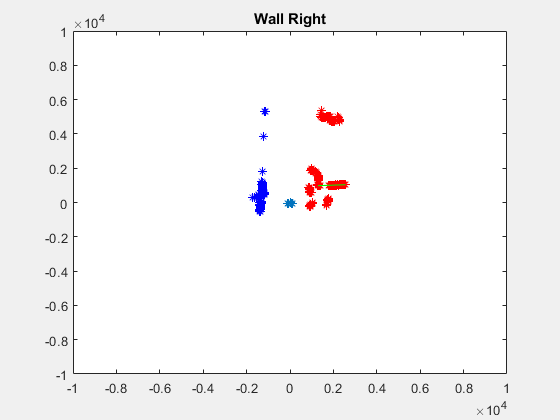

rpoints = 	1.0e+03 *

    0.9268   -0.2218
    0.9213   -0.2145
    0.9217   -0.2087
    0.9200   -0.2024
    0.9193   -0.1963
    0.9175   -0.1900
    0.9187   -0.1844
    0.9227   -0.1793
    0.9258   -0.1740
    0.9288   -0.1687


slope = 0.0434

rpoints = 	1.0e+03 *

    0.9414   -0.2686
    0.9267   -0.2582
    0.9263   -0.2520
    0.9221   -0.2448
    0.9226   -0.2389
    0.9172   -0.2315
    0.9177   -0.2256
    0.9190   -0.2200
    0.9204   -0.2143
    0.9226   -0.2089


slope = 0.0392

rpoints = 	1.0e+03 *

    1.6781   -0.5693
    1.6853   -0.5602
    1.6887   -0.5499
    1.6921   -0.5395
    1.6935   -0.5285
    1.6986   -0.5186
    1.7065   -0.5096
    1.7096   -0.4991
    1.7194   -0.4906
    1.7282   -0.4816


slope = -0.0206

rpoints = 	1.0e+03 *

    1.0329   -0.3085
    1.0233   -0.2988
    1.0203   -0.2911
    1.0259   -0.2859
    1.0276   -0.2796
    1.0235   -0.2717
    1.0262   -0.2657
    1.0278   -0.2594
    1.0274   -0.2526
    1.0289   -0.2463


slope = 5.2512

rpoints = 	1.0e+03 *

    1.4906   -0.3665
    1.4880   -0.3561
    1.4882   -0.3465
    1.4893   -0.3372
    1.4914   -0.3280
    1.4924   -0.3186
    1.4943   -0.3095
    1.4962   -0.3003
    1.5009   -0.2917
    1.5027   -0.2824


slope = 3.5694

rpoints = 	1.0e+03 *

    1.4593   -0.4951
    1.4737   -0.4899
    1.4776   -0.4811
    1.4806   -0.4720
    1.4834   -0.4629
    1.4872   -0.4541
    1.4900   -0.4450
    1.4956   -0.4366
    1.5021   -0.4285
    1.5047   -0.4193


slope = 9.2651

rpoints = 	1.0e+03 *

    1.4887   -0.5050
    1.4917   -0.4959
    1.4957   -0.4870
    1.4987   -0.4778
    1.5016   -0.4686
    1.5054   -0.4597
    1.5082   -0.4504
    1.5109   -0.4411
    1.5136   -0.4318
    1.5162   -0.4225


slope = -0.4389

rpoints = 	1.0e+03 *

    1.4792   -0.5018
    1.4927   -0.4962
    1.4957   -0.4870
    1.4987   -0.4778
    1.5016   -0.4686
    1.4997   -0.4579
    1.5024   -0.4487
    1.5023   -0.4386
    1.5049   -0.4294
    1.5422   -0.4298


slope = -2.0826

rpoints = 	1.0e+03 *

    1.8656   -0.6329
    1.8837   -0.6261
    1.9188   -0.6248
    1.9226   -0.6130
    1.9264   -0.6012
    1.9472   -0.5946
    1.9758   -0.5900
    2.0082   -0.5863
    2.0512   -0.5852
    2.0547   -0.5726


slope = -0.0057

rpoints = 	1.0e+03 *

    2.2983   -0.7797
    2.3116   -0.7684
    2.3315   -0.7591
    2.3361   -0.7448
    2.3407   -0.7304
    2.3451   -0.7161
    2.3495   -0.7016
    1.3976   -0.4081
    1.3972   -0.3986
    1.3958   -0.3890


slope = -1.5425

rpoints = 	1.0e+03 *

    2.6058   -0.8662
    2.6120   -0.8505
    2.6401   -0.8417
    2.6452   -0.8255
    2.6626   -0.8130
    2.6906   -0.8035
    2.7319   -0.7976
    2.7676   -0.7896
    3.9730   -0.7215
    3.9646   -0.6949


slope = -1.3498

rpoints = 	1.0e+03 *

    3.9133   -0.9876
    3.9193   -0.9636
    3.9251   -0.9395
    3.9357   -0.9165
    3.9471   -0.8936
    3.9681   -0.8728
    3.9734   -0.8484
    3.9805   -0.8244
    3.9855   -0.7999
    3.9845   -0.7743


slope = -0.1817

rpoints = 	1.0e+03 *

    3.8575   -1.2822
    3.9033   -1.2709
    3.9186   -1.2229
    3.9261   -1.1988
    3.9417   -1.1246
    3.9485   -1.1004
    3.9089   -1.0635
    3.9115   -1.0384
    3.9023   -1.0104
    3.9085   -0.9864


slope = -0.2694

rpoints = 	1.0e+03 *

    0.2961   -0.0984
    3.4783   -1.1325
    3.7148   -1.1843
    3.7360   -1.1157
    3.7418   -1.0924
    3.7398   -1.0670
    3.7463   -1.0440
    3.7323   -1.0154
    3.7105   -0.9851
    3.6768   -0.9520


slope = -0.3194

rpoints = 	1.0e+03 *

    3.2843   -1.0694
    3.3765   -1.0765
    3.3831   -1.0557
    3.3895   -1.0350
    3.4092   -1.0181
    3.3703   -0.9840
    3.3705   -0.9616
    3.3821   -0.9425
    2.3238    0.7174
    2.2898    0.7223


slope = -0.1670

rpoints = 	1.0e+03 *

    2.4609    0.0265
    2.4277    0.0410
    2.4144    0.0556
    2.4070    0.0702
    2.4045    0.0850
    2.4009    0.0996
    2.4033    0.1145
    2.4045    0.1293
    4.9415    0.8193
    2.1474    0.3696


slope = -0.1200

rpoints = 	1.0e+03 *

    2.5227   -0.4582
    2.5048   -0.4390
    2.5015   -0.4226
    2.5021   -0.4069
    2.5046   -0.3916
    2.5069   -0.3762
    2.5112   -0.3611
    2.2836   -0.2287
    2.2600   -0.2123
    2.2354   -0.1961


slope = -0.1477

rpoints = 	1.0e+03 *

    2.5296   -0.7554
    2.5121   -0.7334
    2.4993   -0.7131
    2.5017   -0.6972
    2.5059   -0.6818
    2.5072   -0.6656
    2.5073   -0.6492
    0.8086   -0.2041
    0.8050   -0.1979
    0.8053   -0.1927


slope = -0.1877

rpoints = 	1.0e+03 *

    0.7671   -0.2602
    0.7895   -0.2624
    0.7911   -0.2576
    0.7927   -0.2527
    0.7990   -0.2493
    0.8005   -0.2444
    0.8020   -0.2395
    0.8035   -0.2346
    0.8049   -0.2296
    0.8082   -0.2252


slope = -0.7242

rpoints = 	1.0e+03 *

    1.7745   -0.5899
    1.7781   -0.5790
    1.7816   -0.5680
    1.7851   -0.5571
    1.7321   -0.5289
    1.7353   -0.5182
    1.6981   -0.4958
    1.4732   -0.4203
    0.8699   -0.2424
    0.8414   -0.2289


slope = -0.0973

rpoints = 	1.0e+03 *

    0.5532   -0.1839
    0.6418   -0.2090
    0.6707   -0.2138
    0.6739   -0.2103
    0.6752   -0.2062
    0.6746   -0.2014
    0.6729   -0.1965
    0.6722   -0.1918
    0.6656   -0.1855
    0.6542   -0.1780


slope = -0.0593

rpoints = 	1.0e+03 *

    0.5871   -0.1992
    0.6235   -0.2072
    0.6399   -0.2084
    0.6412   -0.2044
    0.6520   -0.2035
    0.6561   -0.2003
    0.6583   -0.1966
    0.6595   -0.1925
    0.6741   -0.1923
    0.6762   -0.1884


slope = -0.0558

rpoints = 	1.0e+03 *

    0.6629   -0.2249
    0.6927   -0.2303
    0.6941   -0.2260
    0.6917   -0.2205
    0.6969   -0.2175
    0.7001   -0.2138
    0.7014   -0.2095
    0.7036   -0.2054
    0.7049   -0.2011
    0.7080   -0.1973


slope = -0.0594

rpoints = 	1.0e+03 *

    0.6026   -0.2003
    0.7417   -0.2415
    0.7489   -0.2388
    0.7818   -0.2440
    0.8091   -0.2471
    0.8422   -0.2515
    0.8438   -0.2463
    0.8453   -0.2412
    0.8246   -0.2298
    0.7980   -0.2171


slope = -0.0168

rpoints = 	1.0e+03 *

    1.2500   -0.4241
    1.2849   -0.4271
    1.2903   -0.4201
    1.2929   -0.4122
    1.2973   -0.4048
    1.3045   -0.3983
    1.3089   -0.3909
    1.3324   -0.3890
    1.3674   -0.3901
    1.3910   -0.3876


slope = 0.0043

rpoints = 	1.0e+03 *

    2.0483   -0.6949
    2.0602   -0.6848
    2.0776   -0.6765
    2.0818   -0.6637
    2.0858   -0.6509
    2.1251   -0.6489
    2.1617   -0.6456
    2.2155   -0.6468
    2.2473   -0.6412
    2.2975   -0.6402


slope = 0.0017

rpoints = 	1.0e+03 *

    2.4606   -0.8179
    2.4770   -0.8065
    2.5172   -0.8025
    2.5220   -0.7870
    2.5326   -0.7733
    2.5622   -0.7652
    2.2878    2.5206
    2.2603    2.5212
    2.2308    2.5193
    2.2113    2.5284


slope = 0.0659

rpoints = 	1.0e+03 *

    2.2031    2.3975
    2.1668    2.3873
    2.1468    2.3946
    2.1121    2.3853
    2.0849    2.3839
    2.0598    2.3845
    2.0347    2.3850
    2.0078    2.3829
    1.9682    2.3652
    1.9530    2.3765


slope = 0.1030

rpoints = 	1.0e+03 *

    2.0766    2.2598
    2.0492    2.2577
    2.0200    2.2531
    1.9968    2.2550
    1.9757    2.2589
    1.9343    2.2392
    1.9153    2.2450
    1.8918    2.2452
    1.8601    2.2353
    1.8362    2.2343


slope = 0.1541

rpoints = 	1.0e+03 *

    1.9561    2.0769
    1.9188    2.0625
    1.8891    2.0558
    1.8711    2.0615
    1.8384    2.0506
    1.8112    2.0454
    1.7736    2.0278
    1.7604    2.0379
    1.7271    2.0244
    1.7017    2.0196


slope = 0.2028

rpoints = 	1.0e+03 *

    1.8827    1.9031
    1.8486    1.8917
    1.8231    1.8886
    1.7818    1.8687
    1.7620    1.8709
    1.7280    1.8575
    1.7092    1.8600
    1.6688    1.8386
    1.6555    1.8466
    1.6388    1.8507


slope = 0.2187

rpoints = 	1.0e+03 *

    1.8182    1.7071
    1.7924    1.7038
    1.7733    1.7065
    1.7405    1.6957
    1.7016    1.6783
    1.6743    1.6717
    1.6436    1.6614
    1.6152    1.6528
    1.5960    1.6534
    1.5651    1.6414


slope = 0.2423

rpoints = 	1.0e+03 *

    1.7625    1.5178
    1.7381    1.5155
    1.7130    1.5122
    1.6910    1.5114
    1.6587    1.5009
    1.6185    1.4827
    1.5932    1.4777
    1.5645    1.4689
    1.5366    1.4606
    1.5023    1.4458


slope = 0.2480

rpoints = 	1.0e+03 *

    1.6950    1.3372
    1.6579    1.3245
    1.6311    1.3196
    1.5974    1.3086
    1.5601    1.2942
    1.5314    1.2864
    1.5022    1.2776
    1.4746    1.2698
    1.4434    1.2585
    1.4184    1.2521


slope = 0.2763

rpoints = 	1.0e+03 *

    1.5914    1.1629
    1.5842    1.1727
    1.5138    1.1350
    1.4765    1.1213
    1.4181    1.0907
    1.3774    1.0730
    1.3410    1.0579
    1.3094    1.0461
    1.2734    1.0302
    1.2431    1.0184


slope = 0.3308

rpoints = 	1.0e+03 *

    1.4486    0.9531
    1.4003    0.9337
    1.3481    0.9109
    1.2888    0.8825
    1.2333    0.8556
    1.2084    0.8493
    1.1551    0.8225
    1.1151    0.8044
    1.0916    0.7977
    1.0513    0.7782


slope = 0.4106

rpoints = 	1.0e+03 *

    1.3852    0.8284
    1.2989    0.7876
    1.2063    0.7416
    1.1406    0.7109
    1.0745    0.6789
    1.0206    0.6537
    0.9771    0.6344
    0.9281    0.6107
    0.8761    0.5842
    0.8485    0.5733


slope = -2.4665

rpoints =   923.0096  492.1069
  741.4288  401.1637
  600.4524  329.6694
  525.9074  292.9596
  448.3564  253.3802
  407.7517  233.7489
  375.1869  218.1532
  329.9094  194.5476
  315.8346  188.8717
  314.6686  190.8079


slope = -1.9629

rpoints =   305.3938  -19.2514
  293.5257  -16.6940
  293.6227  -14.8909
  305.6967  -13.6213
  305.7746  -11.7435
  305.8409   -9.8653
  305.8958   -7.9867
  302.9396   -6.0479
  299.9714   -4.1457
  295.9913   -2.2725


slope = -1.7794

rpoints = 	1.0e+03 *

    0.2562   -0.0852
    0.2596   -0.0845
    0.2649   -0.0844
    0.2663   -0.0831
    0.2668   -0.0815
    0.2664   -0.0795
    0.2649   -0.0774
    0.2644   -0.0754
    0.2639   -0.0736
    0.2625   -0.0714


slope = -3.6785

rpoints = 	1.0e+03 *

    0.2557   -0.0867
    0.3198   -0.1063
    0.3252   -0.1059
    0.3297   -0.1051
    0.3265   -0.1019
    0.3309   -0.1010
    0.3315   -0.0990
    0.3321   -0.0970
    0.3279   -0.0936
    0.3275   -0.0913


slope = 0.0516

rpoints = 	1.0e+03 *

    0.2945   -0.0999
    0.3843   -0.1278
    0.3870   -0.1260
    0.3935   -0.1255
    0.3942   -0.1230
    0.3950   -0.1206
    0.3929   -0.1173
    0.3936   -0.1149
    0.3875   -0.1106
    0.3844   -0.1071


slope = -0.0708

rpoints = 	1.0e+03 *

    0.2557   -0.0867
    0.4109   -0.1366
    0.4393   -0.1430
    0.4573   -0.1458
    0.4840   -0.1510
    0.5107   -0.1559
    0.5308   -0.1585
    0.5548   -0.1620
    0.5635   -0.1608
    0.5924   -0.1651


slope = -0.2081

rpoints = 	1.0e+03 *

    2.7476    2.5799
    2.7201    2.5857
    2.7006    2.5989
    2.6774    2.6084
    2.6542    2.6178
    2.6247    2.6206
    2.5987    2.6268
    2.5741    2.6341
    2.5537    2.6455
    2.5354    2.6590


slope = -0.3559

rpoints = 	1.0e+03 *

    3.6249    1.5490
    3.5933    1.5617
    3.5809    1.5825
    3.5502    1.5950
    3.5357    1.6147
    3.5040    1.6263
    3.4840    1.6431
    3.4657    1.6606
    3.4420    1.6753
    3.4262    1.6937


slope = -0.8017

rpoints = 	1.0e+03 *

    4.1666   -0.2113
    4.1389   -0.1844
    4.1230   -0.1583
    4.1179   -0.1328
    4.1006   -0.1071
    4.0762   -0.0814
    4.0736   -0.0563
    4.0659   -0.0312
    4.0490   -0.0062
    4.0330    0.0186


slope = -0.7437

rpoints = 	1.0e+03 *

    3.5690   -1.1864
    3.7959   -1.2359
    3.8405   -1.2244
    3.8528   -1.2023
    3.8601   -1.1786
    3.8711   -1.1560
    3.8781   -1.1322
    3.9658   -1.1315
    4.1325   -1.1516
    4.2833   -1.1653


slope = -0.0061

rpoints = 	1.0e+03 *

    4.2063   -1.1167
    4.2131   -1.0908
    4.2391   -1.0698
    2.2786    0.3205
    2.2746    0.3342
    2.2389    0.3430
    2.1864    0.3487
    2.1842    0.3621
    2.1602    0.3718
    2.1491    0.3835


slope = -0.6498

rpoints = 	1.0e+03 *

    1.8288   -0.2859
    1.8305   -0.2747
    1.8322   -0.2634
    1.8337   -0.2522
    1.8353   -0.2409
    1.7722   -0.2216
    1.7666   -0.2098
    1.7678   -0.1990
    1.7690   -0.1881
    1.7811   -0.1784


slope = -1.7291

rpoints = 	1.0e+03 *

    1.8069   -0.6130
    1.8106   -0.6019
    1.8143   -0.5907
    1.8140   -0.5783
    1.8156   -0.5666
    1.8134   -0.5537
    1.8119   -0.5411
    1.8104   -0.5286
    1.8127   -0.5172
    1.8100   -0.5044


slope = -0.8010

rpoints = 202×2
  916.6881 -310.9775
  927.1213 -308.1803
  935.6527 -304.6475
  937.5061 -298.8950
  945.0518 -294.9187
  953.5402 -291.1530
  956.2686 -285.5771
  963.7641 -281.3800
  965.4742 -275.4553
  960.4047 -267.6412


slope = -0.5651

rpoints = 145×2
	1.0e+03 *

    2.6496    0.3893
    2.5166    0.3855
    2.5142    0.4010
    2.5117    0.4164
    2.5288    0.4352
    2.5310    0.4516
    2.5489    0.4710
    2.5479    0.4870
    2.5723    0.5081
    2.6093    0.5321


slope = -0.3204

rpoints = 156×2
	1.0e+03 *

    2.4429   -0.0188
    2.4430   -0.0038
    2.4430    0.0113
    2.4489    0.0263
    2.4576    0.0415
    2.4633    0.0567
    2.4640    0.0719
    2.4884    0.0879
    2.5008    0.1037
    2.8991    0.7983


slope = -0.2869

rpoints = 154×2
	1.0e+03 *

    2.3408   -0.0755
    2.2392   -0.0585
    2.2396   -0.0447
    2.2398   -0.0310
    2.2539   -0.0173
    2.2580   -0.0035
    2.2580    0.0104
    2.2639    0.0243
    2.2677    0.0383
    2.2704    0.0523


slope = 0.1871

rpoints = 144×2
	1.0e+03 *

    1.9825   -0.2232
    1.9838   -0.2110
    1.9841   -0.1987
    1.9863   -0.1866
    1.9874   -0.1744
    1.9924   -0.1625
    1.9933   -0.1503
    1.9942   -0.1380
    1.9950   -0.1258
    1.9968   -0.1136


slope = -0.1937

rpoints = 132×2
	1.0e+03 *

    1.8384   -0.2759
    1.8341   -0.2637
    1.8357   -0.2524
    1.8372   -0.2412
    1.8417   -0.2302
    1.8401   -0.2186
    1.8444   -0.2076
    1.8406   -0.1957
    1.8468   -0.1849
    1.8479   -0.1736


slope = 0.4657

rpoints = 144×2
	1.0e+03 *

    1.6686   -0.5661
    1.6720   -0.5558
    1.6754   -0.5455
    1.6549   -0.5276
    1.6581   -0.5174
    1.6613   -0.5073
    1.6634   -0.4968
    1.6568   -0.4837
    1.6502   -0.4708
    1.6501   -0.4598


slope = -8.2124

rpoints = 135×2
	1.0e+03 *

    4.4933    0.3248
    1.5173    0.1191
    1.5156    0.1283
    1.5148    0.1376
    1.5149    0.1470
    1.5169    0.1566
    1.5159    0.1659
    1.5149    0.1752
    1.5098    0.1840
    1.5077    0.1932


slope = -7.4378

rpoints = 178×2
	1.0e+03 *

    3.7244   -0.8673
    3.7247   -0.8433
    3.7279   -0.8200
    1.2723   -0.2717
    1.2671   -0.2624
    1.2687   -0.2546
    1.2761   -0.2480
    1.2786   -0.2403
    1.2791   -0.2323
    1.2805   -0.2244


slope = -2.9612

rpoints = 181×2
	1.0e+03 *

    1.1695   -0.3968
    1.1776   -0.3915
    1.1905   -0.3876
    1.1928   -0.3803
    1.1971   -0.3736
    1.1993   -0.3662
    1.2016   -0.3588
    1.2018   -0.3509
    1.2020   -0.3429
    1.2022   -0.3350


slope = -6.6787

rpoints = 143×2
	1.0e+03 *

    0.9972   -0.3383
    1.0230   -0.3400
    1.0326   -0.3362
    1.0347   -0.3299
    1.0424   -0.3253
    1.0492   -0.3204
    1.0521   -0.3142
    1.0598   -0.3094
    3.9930   -0.0061
    1.0110    0.0047


slope = -0.9398

rpoints = 153×2
	1.0e+03 *

    3.8739   -0.6056
    1.0552   -0.1583
    1.0561   -0.1518
    1.0749   -0.1478
    1.0758   -0.1412
    1.1689   -0.1461
    1.1698   -0.1390
    1.1706   -0.1318
    1.1565   -0.1230
    1.1572   -0.1159


slope = -1.7381

rpoints = 137×2
	1.0e+03 *

    1.1326   -0.3842
    1.1558   -0.3842
    1.1658   -0.3796
    1.1604   -0.3700
    1.1703   -0.3652
    1.1949   -0.3568
    1.1970   -0.3495
    1.2078   -0.3446
    1.2099   -0.3372
    1.2119   -0.3297


slope = 6.8566

rpoints = 79×2
  813.4660 -275.9604
  852.1545 -283.2609
  853.8782 -278.0218
  855.5696 -272.7721
  859.1380 -268.1079
  869.3762 -265.4544
  876.7393 -261.8267
  881.2106 -257.2777
  884.6974 -252.4093
  892.0108 -248.5815


slope = 1.1744

rpoints = 67×2
	1.0e+03 *

    0.3378   -0.1123
    3.4821   -1.1338
    3.5528   -1.1327
    1.3301   -0.3444
    1.3322   -0.3362
    1.3343   -0.3280
    1.3431   -0.3215
    1.3538   -0.3152
    1.3557   -0.3069
    1.3488   -0.2967


slope = 4.2629

rpoints = 97×2
	1.0e+03 *

    3.8125   -0.8631
    3.7504   -0.8249
    3.7465   -0.8000
    3.7514   -0.7769
    3.7561   -0.7539
    3.7813   -0.7348
    3.7975   -0.7138
    3.8038   -0.6908
    3.8060   -0.6671
    3.8327   -0.6475


slope = 4.8424

rpoints = 120×2
	1.0e+03 *

    3.9569   -0.6685
    1.4973   -0.2435
    1.5057   -0.2354
    1.5071   -0.2261
    1.5085   -0.2169
    1.5098   -0.2076
    1.5110   -0.1983
    1.4775   -0.1847
    1.4786   -0.1756
    1.4797   -0.1666


slope = 9.1988

rpoints = 141×2
	1.0e+03 *

    3.7555   -1.0217
    3.7617   -0.9987
    3.7678   -0.9755
    3.7737   -0.9524
    3.8601   -0.9490
    2.5809   -0.3066
    2.6264   -0.2956
    2.6282   -0.2795
    2.6239   -0.2628
    2.6314   -0.2472


slope = 7.7717

rpoints = 153×2
	1.0e+03 *

    0.3312   -0.1101
    1.4636   -0.4176
    1.4661   -0.4086
    1.4686   -0.3996
    1.4710   -0.3905
    1.4734   -0.3815
    1.4767   -0.3727
    1.4935   -0.3672
    1.5065   -0.3606
    1.5086   -0.3513


slope = 12.4512

rpoints = 139×2
	1.0e+03 *

    1.4347   -0.4867
    1.4377   -0.4779
    1.4406   -0.4690
    1.4434   -0.4602
    1.4491   -0.4522
    1.4547   -0.4442
    1.4593   -0.4358
    1.4620   -0.4268
    1.4646   -0.4178
    1.4632   -0.4078


slope = 2.7955

rpoints = 127×2
	1.0e+03 *

    1.4527   -0.4928
    1.4823   -0.4927
    1.4862   -0.4839
    1.4891   -0.4748
    1.5054   -0.4698
    1.5083   -0.4605
    1.5111   -0.4513
    1.5138   -0.4420
    1.5146   -0.4321
    1.5133   -0.4217


slope = 5.0003

rpoints = 158×2
	1.0e+03 *

    1.4252   -0.4835
    1.4433   -0.4798
    1.4529   -0.4731
    1.4558   -0.4641
    1.4663   -0.4576
    1.4690   -0.4486
    1.4718   -0.4395
    1.4610   -0.4266
    1.4636   -0.4176
    1.4642   -0.4080


slope = -0.3040

rpoints = 168×2
	1.0e+03 *

    1.4461   -0.4906
    1.4604   -0.4855
    1.4634   -0.4765
    1.4606   -0.4657
    1.4682   -0.4582
    1.4662   -0.4477
    1.4670   -0.4381
    1.4581   -0.4257
    1.4607   -0.4167
    1.4526   -0.4048


slope = -2.2966

rpoints = 180×2
	1.0e+03 *

    3.7185   -1.1354
    3.5721   -1.0668
    3.5786   -1.0448
    3.5849   -1.0228
    3.6162   -1.0077
    2.7299   -0.5305
    2.6712   -0.5021
    2.6300   -0.4776
    2.5846   -0.4530
    2.5686   -0.4340


slope = -0.5726

rpoints = 149×2
	1.0e+03 *

    5.2717   -1.6097
    3.8749   -1.1572
    3.8733   -1.1308
    3.8802   -1.1070
    3.8869   -1.0832
    3.9031   -1.0619
    3.9888   -1.0590
    4.1230   -1.0675
    4.1334   -1.0432
    4.1562   -1.0218


slope = 0.0418

rpoints = 131×2
	1.0e+03 *

    2.6043   -0.7952
    2.4989   -0.7463
    2.5006   -0.7301
    2.5079   -0.7155
    2.5123   -0.7001
    2.5233   -0.6865
    2.5371   -0.6736
    2.5422   -0.6582
    2.5462   -0.6426
    2.5520   -0.6274


slope = 0.6977

rpoints = 187×2
	1.0e+03 *

    2.6320   -0.8570
    2.6372   -0.8408
    2.6423   -0.8246
    2.4714   -0.7546
    2.3562   -0.7036
    2.1992   -0.6421
    2.0983   -0.5986
    2.0162   -0.5619
    1.9443   -0.5290
    1.8557   -0.4927


slope = 2.4567

rpoints = 192×2
	1.0e+03 *

    3.3625    0.0568
    3.3621    0.0775
    2.4390    0.0712
    2.2966    0.0811
    2.0972    0.0870
    1.9877    0.0947
    1.9022    0.1023
    1.8048    0.1082
    1.7352    0.1147
    1.6537    0.1196


slope = -0.1633

rpoints = 189×2
	1.0e+03 *

    3.0841   -1.0252
    3.1188   -1.0155
    3.4099    0.3520
    3.4076    0.3730
    3.4053    0.3939
    3.4028    0.4148
    3.4002    0.4357
    2.3836    0.3203
    2.2607    0.3180
    2.1568    0.3169


slope = -0.0388

rpoints = 171×2
	1.0e+03 *

    2.3756    0.3341
    2.2588    0.3318
    2.1331    0.3268
    2.0205    0.3222
    1.9346    0.3207
    1.8380    0.3163
    1.7789    0.3174
    1.6904    0.3124
    1.6157    0.3088
    1.5599    0.3081


slope = -0.0361

rpoints = 165×2
	1.0e+03 *

    2.9740   -0.9886
    2.3523    0.3752
    2.2414    0.3716
    2.1287    0.3664
    2.0201    0.3605
    1.9362    0.3578
    1.8525    0.3541
    1.7953    0.3546
    1.7196    0.3506
    1.6245    0.3416


slope = -0.0481

rpoints = 153×2
	1.0e+03 *

    2.3318    0.4457
    2.2172    0.4379
    2.1116    0.4306
    2.0159    0.4240
    1.9576    0.4243
    1.8593    0.4149
    1.7816    0.4091
    1.6905    0.3991
    1.6288    0.3951
    1.5545    0.3872


slope = 0.0086

rpoints = 147×2
	1.0e+03 *

    2.4190    0.4010
    2.2805    0.3925
    2.1924    0.3912
    2.0719    0.3829
    2.0008    0.3824
    1.9140    0.3780
    1.8137    0.3698
    1.7448    0.3670
    1.6839    0.3650
    1.6094    0.3592


slope = 0.0514

rpoints = 147×2
	1.0e+03 *

    2.5088    0.4159
    2.3189    0.3991
    2.2209    0.3963
    2.1231    0.3923
    2.0155    0.3852
    1.9160    0.3784
    1.8480    0.3768
    1.7556    0.3692
    1.6839    0.3650
    1.6289    0.3635


slope = -0.0326

rpoints = 145×2
	1.0e+03 *

    2.4792    0.4110
    2.3307    0.4011
    2.2091    0.3942
    2.1054    0.3890
    2.0293    0.3879
    1.9297    0.3812
    1.8617    0.3796
    1.7566    0.3694
    1.6956    0.3675
    1.6367    0.3653


slope = -0.0367

rpoints = 136×2
	1.0e+03 *

    2.4752    0.4104
    2.3435    0.4033
    2.2130    0.3949
    2.0926    0.3867
    2.0165    0.3854
    1.9297    0.3812
    1.8578    0.3788
    1.7722    0.3727
    1.7064    0.3698
    1.6377    0.3655


slope = -0.0085

rpoints = 137×2
	1.0e+03 *

    2.5354    0.4203
    2.3337    0.4016
    2.2347    0.3988
    2.1172    0.3912
    2.0234    0.3868
    1.9317    0.3815
    1.8588    0.3790
    1.7703    0.3723
    1.6986    0.3681
    1.6221    0.3620


slope = 0.0575

rpoints = 145×2
	1.0e+03 *

    2.4851    0.4120
    2.3199    0.3993
    2.2209    0.3963
    2.1063    0.3892
    2.0224    0.3866
    1.9327    0.3817
    1.8627    0.3798
    1.7752    0.3733
    1.7044    0.3694
    1.6289    0.3635


slope = -0.0207

rpoints = 140×2
	1.0e+03 *

    2.3258    0.4003
    2.2052    0.3935
    2.1073    0.3894
    2.0244    0.3869
    1.9101    0.3773
    1.8725    0.3818
    1.7644    0.3711
    1.7025    0.3690
    1.6484    0.3679
    1.5604    0.3583


slope = 0.0522

rpoints = 135×2
	1.0e+03 *

    2.4861    0.4122
    2.3248    0.4001
    2.2249    0.3970
    2.1083    0.3896
    2.0185    0.3858
    1.9189    0.3790
    1.8529    0.3778
    1.7556    0.3692
    1.7005    0.3686
    1.6260    0.3629


slope = 0.0563

rpoints = 126×2
	1.0e+03 *

    2.4930    0.4133
    2.3327    0.4015
    2.2140    0.3951
    2.1231    0.3923
    2.0253    0.3871
    1.9248    0.3802
    1.8490    0.3770
    1.7605    0.3702
    1.7005    0.3686
    1.6280    0.3633


slope = 0.0557

rpoints = 136×2
	1.0e+03 *

    2.4890    0.4127
    2.3357    0.4020
    2.2239    0.3968
    2.1201    0.3918
    2.0361    0.3892
    1.9336    0.3819
    1.8548    0.3782
    1.7859    0.3756
    1.6917    0.3667
    1.6338    0.3646


slope = -19.0010

rpoints = 135×2
	1.0e+03 *

    5.4940    0.9109
    2.3554    0.4054
    2.2209    0.3963
    2.1250    0.3927
    2.0253    0.3871
    1.9415    0.3835
    1.8597    0.3792
    1.7703    0.3723
    1.7025    0.3690
    1.6270    0.3631


slope = 0.0566

rpoints = 142×2
	1.0e+03 *

    2.5018    0.4148
    2.3366    0.4022
    2.2170    0.3956
    2.1191    0.3916
    2.0420    0.3903
    1.9327    0.3817
    1.8597    0.3792
    1.7732    0.3729
    1.7044    0.3694
    1.6377    0.3655


slope = 0.0571

rpoints = 134×2
	1.0e+03 *

    2.4811    0.4113
    2.3376    0.4023
    2.2337    0.3986
    2.1113    0.3901
    2.0352    0.3890
    1.9317    0.3815
    1.8529    0.3778
    1.7742    0.3731
    1.7054    0.3696
    1.6250    0.3627


slope = 0.0565

rpoints = 125×2
	1.0e+03 *

    2.4999    0.4145
    2.3327    0.4015
    2.2278    0.3975
    2.1044    0.3889
    2.0145    0.3851
    1.9336    0.3819
    1.8441    0.3760
    1.7703    0.3723
    1.6976    0.3679
    1.6436    0.3668


slope = 0.0558

rpoints = 129×2
	1.0e+03 *

    2.5166    0.4172
    2.3219    0.3996
    2.2229    0.3966
    2.1231    0.3923
    2.0293    0.3879
    1.9346    0.3821
    1.8558    0.3784
    1.7752    0.3733
    1.6947    0.3673
    1.6260    0.3629


slope = 0.0513

rpoints = 126×2
	1.0e+03 *

    2.5206    0.4179
    2.3327    0.4015
    2.2199    0.3961
    2.1221    0.3921
    2.0450    0.3909
    1.9327    0.3817
    1.8539    0.3780
    1.7752    0.3733
    1.7054    0.3696
    1.6367    0.3653


slope = 0.0540

rpoints = 126×2
	1.0e+03 *

    2.4999    0.4145
    2.3140    0.3983
    2.2111    0.3945
    2.1103    0.3899
    2.0263    0.3873
    1.9464    0.3844
    1.8441    0.3760
    1.7732    0.3729
    1.7025    0.3690
    1.6387    0.3657


slope = 0.0548

rpoints = 128×2
	1.0e+03 *

    2.5018    0.4148
    2.3514    0.4047
    2.2288    0.3977
    2.1122    0.3903
    2.0361    0.3892
    1.9317    0.3815
    1.8529    0.3778
    1.7859    0.3756
    1.6976    0.3679
    1.6348    0.3648


slope = 0.0543

rpoints = 125×2
	1.0e+03 *

    2.4703    0.4095
    2.3347    0.4018
    2.2190    0.3959
    2.1280    0.3932
    2.0244    0.3869
    1.9278    0.3808
    1.8607    0.3794
    1.7693    0.3721
    1.6976    0.3679
    1.6358    0.3651


slope = 0.0532

rpoints = 124×2
	1.0e+03 *

    2.5097    0.4161
    2.3416    0.4030
    2.2071    0.3938
    2.1122    0.3903
    2.0371    0.3894
    1.9317    0.3815
    1.8578    0.3788
    1.7673    0.3717
    1.6927    0.3669
    1.6299    0.3637


slope = 0.0566

rpoints = 126×2
	1.0e+03 *

    2.5048    0.4153
    2.3209    0.3994
    2.2199    0.3961
    2.1280    0.3932
    2.0263    0.3873
    1.9248    0.3802
    1.8744    0.3822
    1.7781    0.3740
    1.7044    0.3694
    1.6270    0.3631


slope = 0.0540

rpoints = 128×2
	1.0e+03 *

    2.4713    0.4097
    2.3307    0.4011
    2.2170    0.3956
    2.1004    0.3881
    2.0194    0.3860
    1.9385    0.3829
    1.8529    0.3778
    1.7732    0.3729
    1.6995    0.3683
    1.6319    0.3642


slope = 0.0544

rpoints = 128×2
	1.0e+03 *

    2.4910    0.4130
    2.3169    0.3988
    2.2180    0.3958
    2.1290    0.3934
    2.0204    0.3862
    1.9356    0.3823
    1.8568    0.3786
    1.7713    0.3725
    1.7054    0.3696
    1.6270    0.3631


slope = 0.0554

rpoints = 125×2
	1.0e+03 *

    2.5206    0.4179
    2.3288    0.4008
    2.2337    0.3986
    2.1201    0.3918
    2.0175    0.3856
    1.9258    0.3804
    1.8558    0.3784
    1.7654    0.3713
    1.7005    0.3686
    1.6533    0.3690


slope = 0.0567

rpoints = 123×2
	1.0e+03 *

    2.4693    0.4094
    2.3465    0.4039
    2.2199    0.3961
    2.1103    0.3899
    2.0116    0.3845
    1.9376    0.3827
    1.8490    0.3770
    1.7713    0.3725
    1.6947    0.3673
    1.6299    0.3637


slope = 0.0555

rpoints = 126×2
	1.0e+03 *

    2.4644    0.4086
    2.3159    0.3986
    2.2239    0.3968
    2.1191    0.3916
    2.0263    0.3873
    1.9297    0.3812
    1.8607    0.3794
    1.7585    0.3698
    1.6986    0.3681
    1.6309    0.3640


slope = 0.0513

rpoints = 118×2
	1.0e+03 *

    2.4644    0.4086
    2.3228    0.3998
    2.2239    0.3968
    2.1250    0.3927
    2.0155    0.3852
    1.9258    0.3804
    1.8695    0.3812
    1.7742    0.3731
    1.6956    0.3675
    1.6289    0.3635


slope = 0.0544

rpoints = 121×2
	1.0e+03 *

    2.4861    0.4122
    2.3376    0.4023
    2.2239    0.3968
    2.1221    0.3921
    2.0224    0.3866
    1.9219    0.3796
    1.8607    0.3794
    1.7703    0.3723
    1.7025    0.3690
    1.6270    0.3631


slope = 0.0556

rpoints = 128×2
	1.0e+03 *

    2.4851    0.4120
    2.3258    0.4003
    2.2199    0.3961
    2.1063    0.3892
    2.0371    0.3894
    1.9317    0.3815
    1.8568    0.3786
    1.7624    0.3707
    1.7035    0.3692
    1.6358    0.3651


slope = 0.0548

rpoints = 121×2
	1.0e+03 *

    5.4970    0.9113
    2.3248    0.4001
    2.2337    0.3986
    2.1250    0.3927
    2.0332    0.3886
    1.9307    0.3813
    1.8578    0.3788
    1.7703    0.3723
    1.7025    0.3690
    1.6309    0.3640


slope = 0.0559

rpoints = 126×2
	1.0e+03 *

    2.5018    0.4148
    2.3386    0.4025
    2.2160    0.3954
    2.1270    0.3930
    2.0244    0.3869
    1.9219    0.3796
    1.8558    0.3784
    1.7624    0.3707
    1.7074    0.3700
    1.6309    0.3640


slope = 0.0562

rpoints = 124×2
	1.0e+03 *

    2.5028    0.4149
    2.3327    0.4015
    2.2209    0.3963
    2.1181    0.3914
    2.0145    0.3851
    1.9229    0.3798
    1.8529    0.3778
    1.7781    0.3740
    1.7025    0.3690
    1.6319    0.3642


slope = 0.0554

rpoints = 126×2
	1.0e+03 *

    2.5088    0.4159
    2.3386    0.4025
    2.2101    0.3944
    2.1162    0.3910
    2.0204    0.3862
    1.9248    0.3802
    1.8597    0.3792
    1.7742    0.3731
    1.7132    0.3713
    1.6358    0.3651


slope = 0.0555

rpoints = 124×2
	1.0e+03 *

    2.4811    0.4113
    2.3347    0.4018
    2.2367    0.3991
    2.1270    0.3930
    2.0371    0.3894
    1.9356    0.3823
    1.8607    0.3794
    1.7810    0.3746
    1.7025    0.3690
    1.6377    0.3655


slope = 0.0561

rpoints = 126×2
	1.0e+03 *

    2.4871    0.4123
    2.3130    0.3981
    2.2121    0.3947
    2.1349    0.3945
    2.0263    0.3873
    1.9327    0.3817
    1.8578    0.3788
    1.7673    0.3717
    1.7044    0.3694
    1.6338    0.3646


slope = 0.0549

rpoints = 129×2
	1.0e+03 *

    2.5097    0.4161
    2.3120    0.3979
    2.2219    0.3965
    2.1231    0.3923
    2.0312    0.3883
    1.9209    0.3794
    1.8578    0.3788
    1.7703    0.3723
    1.6986    0.3681
    1.6358    0.3651


slope = 0.0556

rpoints = 119×2
	1.0e+03 *

    2.5226    0.4182
    2.3258    0.4003
    2.2278    0.3975
    2.1240    0.3925
    2.0302    0.3881
    1.9238    0.3800
    1.8490    0.3770
    1.7693    0.3721
    1.6986    0.3681
    1.6231    0.3622


slope = 0.0560

rpoints = 127×2
	1.0e+03 *

    2.5028    0.4149
    2.3159    0.3986
    2.2199    0.3961
    2.1113    0.3901
    2.0352    0.3890
    1.9229    0.3798
    1.8597    0.3792
    1.7722    0.3727
    1.6927    0.3669
    1.6250    0.3627


slope = 0.0557

rpoints = 126×2
	1.0e+03 *

    2.4930    0.4133
    2.3278    0.4006
    2.2357    0.3989
    2.1122    0.3903
    2.0293    0.3879
    1.9219    0.3796
    1.8578    0.3788
    1.7722    0.3727
    1.6976    0.3679
    1.6358    0.3651


slope = 0.0532

rpoints = 126×2
	1.0e+03 *

    2.4653    0.4087
    2.3169    0.3988
    2.2199    0.3961
    2.1240    0.3925
    2.0371    0.3894
    1.9336    0.3819
    1.8588    0.3790
    1.7840    0.3752
    1.7005    0.3686
    1.6416    0.3664


slope = 0.0546

rpoints = 122×2
	1.0e+03 *

    2.4782    0.4109
    2.3268    0.4005
    2.2239    0.3968
    2.1231    0.3923
    2.0410    0.3901
    1.9356    0.3823
    1.8470    0.3766
    1.7693    0.3721
    1.6917    0.3667
    1.6367    0.3653


slope = 0.0552

rpoints = 120×2
	1.0e+03 *

    2.4940    0.4135
    2.3337    0.4016
    2.2278    0.3975
    2.1172    0.3912
    2.0204    0.3862
    1.9336    0.3819
    1.8421    0.3756
    1.7664    0.3715
    1.6878    0.3658
    1.6387    0.3657


slope = 0.0557

rpoints = 124×2
	1.0e+03 *

    2.4801    0.4112
    2.3307    0.4011
    2.2219    0.3965
    2.1280    0.3932
    2.0224    0.3866
    1.9238    0.3800
    1.8617    0.3796
    1.7546    0.3690
    1.7064    0.3698
    1.6358    0.3651


slope = 0.0524

rpoints = 125×2
	1.0e+03 *

    2.4703    0.4095
    2.3445    0.4035
    2.2190    0.3959
    2.1240    0.3925
    2.0244    0.3869
    1.9346    0.3821
    1.8441    0.3760
    1.7810    0.3746
    1.6986    0.3681
    1.6280    0.3633


slope = 0.0526

rpoints = 123×2
	1.0e+03 *

    2.5097    0.4161
    2.3366    0.4022
    2.2219    0.3965
    2.1211    0.3919
    2.0273    0.3875
    2.0249    0.3999
    1.9313    0.3938
    1.8564    0.3904
    1.7005    0.3686
    1.6416    0.3664


slope = 0.0595

rpoints = 127×2
	1.0e+03 *

    2.4772    0.4107
    2.3327    0.4015
    2.2426    0.4002
    2.1044    0.3889
    2.0224    0.3866
    1.9327    0.3817
    1.8499    0.3772
    1.7615    0.3705
    1.6976    0.3679
    1.6426    0.3666


slope = 0.0548

rpoints = 126×2
	1.0e+03 *

    2.4989    0.4143
    2.3209    0.3994
    2.2160    0.3954
    2.1162    0.3910
    2.0224    0.3866
    1.9376    0.3827
    1.8539    0.3780
    1.7664    0.3715
    1.6956    0.3675
    1.6319    0.3642


slope = 0.0558

rpoints = 127×2
	1.0e+03 *

    2.4969    0.4140
    2.3337    0.4016
    2.2170    0.3956
    2.1240    0.3925
    2.0155    0.3852
    1.9287    0.3810
    1.8490    0.3770
    1.7634    0.3709
    1.6956    0.3675
    1.6270    0.3631


slope = 0.0548

rpoints = 124×2
	1.0e+03 *

    2.5107    0.4163
    2.3297    0.4010
    2.2317    0.3982
    2.1240    0.3925
    2.0175    0.3856
    1.9179    0.3788
    1.8519    0.3776
    1.7742    0.3731
    1.6898    0.3662
    1.6309    0.3640


slope = 0.0557

rpoints = 120×2
	1.0e+03 *

    2.4841    0.4118
    2.3366    0.4022
    2.2219    0.3965
    2.1103    0.3899
    2.0185    0.3858
    1.9336    0.3819
    1.8470    0.3766
    1.7605    0.3702
    1.6927    0.3669
    1.6309    0.3640


slope = 0.0557

rpoints = 125×2
	1.0e+03 *

    2.4890    0.4127
    2.3238    0.4000
    2.2229    0.3966
    2.1270    0.3930
    2.0116    0.3845
    1.9366    0.3825
    1.8499    0.3772
    1.7683    0.3719
    1.7025    0.3690
    1.6338    0.3646


slope = 0.0546

rpoints = 128×2
	1.0e+03 *

    2.5058    0.4154
    2.3366    0.4022
    2.2042    0.3933
    2.1132    0.3905
    2.0175    0.3856
    1.9287    0.3810
    1.8656    0.3804
    1.7722    0.3727
    1.6917    0.3667
    1.6387    0.3657


slope = 0.0562

rpoints = 120×2
	1.0e+03 *

    2.4851    0.4120
    2.3150    0.3984
    2.2180    0.3958
    2.1280    0.3932
    2.0322    0.3884
    1.9346    0.3821
    1.8588    0.3790
    1.7752    0.3733
    1.7132    0.3713
    1.6240    0.3624


slope = 0.0525

rpoints = 126×2
	1.0e+03 *

    2.5166    0.4172
    2.3327    0.4015
    2.2377    0.3993
    2.1034    0.3887
    2.0234    0.3868
    1.9268    0.3806
    1.8656    0.3804
    1.7644    0.3711
    1.6947    0.3673
    1.6358    0.3651


slope = 0.0568

rpoints = 127×2
	1.0e+03 *

    2.4742    0.4102
    2.3317    0.4013
    2.2101    0.3944
    2.1191    0.3916
    2.0244    0.3869
    1.9307    0.3813
    1.8460    0.3764
    1.7771    0.3737
    1.6986    0.3681
    1.6358    0.3651


slope = 0.0547

rpoints = 125×2
	1.0e+03 *

    2.5068    0.4156
    2.3120    0.3979
    2.2209    0.3963
    2.1191    0.3916
    2.0165    0.3854
    1.9356    0.3823
    1.8392    0.3750
    1.7801    0.3744
    1.7064    0.3698
    1.6416    0.3664


slope = 0.0531

rpoints = 123×2
	1.0e+03 *

    2.4861    0.4122
    2.3337    0.4016
    2.2367    0.3991
    2.1231    0.3923
    2.0165    0.3854
    1.9287    0.3810
    1.8460    0.3764
    1.7634    0.3709
    1.6966    0.3677
    1.6328    0.3644


slope = 0.0557

rpoints = 124×2
	1.0e+03 *

    2.5176    0.4174
    2.3327    0.4015
    2.2249    0.3970
    2.1250    0.3927
    2.0273    0.3875
    1.9376    0.3827
    1.8627    0.3798
    1.7536    0.3688
    1.6976    0.3679
    1.6319    0.3642


slope = 0.0561

rpoints = 121×2
	1.0e+03 *

    2.4841    0.4118
    2.3248    0.4001
    2.2249    0.3970
    2.1142    0.3907
    2.0273    0.3875
    1.9336    0.3819
    1.8470    0.3766
    1.7703    0.3723
    1.6956    0.3675
    1.6289    0.3635


slope = 0.0555

rpoints = 123×2
	1.0e+03 *

    2.4752    0.4104
    2.3159    0.3986
    2.2180    0.3958
    2.1309    0.3938
    2.0263    0.3873
    1.9385    0.3829
    1.8529    0.3778
    1.7889    0.3762
    1.7005    0.3686
    1.6436    0.3668


slope = 0.0525

rpoints = 125×2
	1.0e+03 *

    5.4999    0.9118
    2.3386    0.4025
    2.2357    0.3989
    2.1093    0.3898
    2.0322    0.3884
    1.9356    0.3823
    1.8646    0.3802
    1.7683    0.3719
    1.7054    0.3696
    1.6377    0.3655


slope = 0.0532

rpoints = 122×2
	1.0e+03 *

    2.5078    0.4158
    2.3248    0.4001
    2.2140    0.3951
    2.1113    0.3901
    2.0381    0.3896
    1.9454    0.3843
    1.8441    0.3760
    1.7761    0.3735
    1.6966    0.3677
    1.6319    0.3642


slope = 0.0559

rpoints = 124×2
	1.0e+03 *

    2.4742    0.4102
    2.3337    0.4016
    2.2170    0.3956
    2.1231    0.3923
    2.0263    0.3873
    1.9415    0.3835
    1.8666    0.3806
    1.7566    0.3694
    1.7093    0.3705
    1.6445    0.3670


slope = 0.0541

rpoints = 123×2
	1.0e+03 *

    2.5107    0.4163
    2.3327    0.4015
    2.2180    0.3958
    2.0985    0.3878
    2.0302    0.3881
    1.9346    0.3821
    1.8607    0.3794
    1.7781    0.3740
    1.7005    0.3686
    1.6348    0.3648


slope = 0.0559

rpoints = 125×2
	1.0e+03 *

    2.4821    0.4115
    2.3248    0.4001
    2.2199    0.3961
    2.1231    0.3923
    2.0165    0.3854
    1.9493    0.3850
    1.8715    0.3816
    1.7703    0.3723
    1.6966    0.3677
    1.6280    0.3633


slope = 0.0526

rpoints = 124×2
	1.0e+03 *

    2.4979    0.4141
    2.3386    0.4025
    2.2209    0.3963
    2.1221    0.3921
    2.0263    0.3873
    1.9179    0.3788
    1.8539    0.3780
    1.7664    0.3715
    1.6956    0.3675
    1.6260    0.3629


slope = 0.0559

rpoints = 123×2
	1.0e+03 *

    2.5117    0.4164
    2.3169    0.3988
    2.2268    0.3974
    2.1201    0.3918
    2.0322    0.3884
    1.9317    0.3815
    1.8588    0.3790
    1.7713    0.3725
    1.6888    0.3660
    1.6377    0.3655


slope = 0.0562

rpoints = 118×2
	1.0e+03 *

    2.4910    0.4130
    2.3386    0.4025
    2.2337    0.3986
    2.1063    0.3892
    2.0263    0.3873
    1.9258    0.3804
    1.8548    0.3782
    1.7752    0.3733
    1.7044    0.3694
    1.6358    0.3651


slope = 0.0552

rpoints = 121×2
	1.0e+03 *

    2.4910    0.4130
    2.3426    0.4032
    2.2258    0.3972
    2.1250    0.3927
    2.0194    0.3860
    1.9170    0.3786
    1.8490    0.3770
    1.7801    0.3744
    1.6917    0.3667
    1.6260    0.3629


slope = 0.0551

rpoints = 129×2
	1.0e+03 *

    2.5216    0.4181
    2.3169    0.3988
    2.2249    0.3970
    2.1221    0.3921
    2.0253    0.3871
    1.9405    0.3833
    1.8666    0.3806
    1.7742    0.3731
    1.7015    0.3688
    1.6377    0.3655


slope = 0.0537

rpoints = 124×2
	1.0e+03 *

    2.3130    0.3981
    2.2160    0.3954
    2.1162    0.3910
    2.0293    0.3879
    1.9425    0.3837
    1.8666    0.3806
    1.7713    0.3725
    1.6937    0.3671
    1.6231    0.3622
    1.5643    0.3592


slope = 0.0532

rpoints = 129×2
	1.0e+03 *

    2.4851    0.4120
    2.3051    0.3967
    2.2170    0.3956
    2.1231    0.3923
    2.0410    0.3901
    1.9346    0.3821
    1.8548    0.3782
    1.7664    0.3715
    1.6956    0.3675
    1.6280    0.3633


slope = 0.0524

rpoints = 127×2
	1.0e+03 *

    2.4920    0.4131
    2.3317    0.4013
    2.2190    0.3959
    2.1181    0.3914
    2.0204    0.3862
    1.9513    0.3854
    1.8735    0.3820
    1.7732    0.3729
    1.7142    0.3715
    1.6201    0.3616


slope = 0.0536

rpoints = 125×2
	1.0e+03 *

    2.5009    0.4146
    2.3268    0.4005
    2.2327    0.3984
    2.1063    0.3892
    2.0214    0.3864
    1.9160    0.3784
    1.8617    0.3796
    1.7830    0.3750
    1.7025    0.3690
    1.6211    0.3618


slope = 0.0557

rpoints = 127×2
	1.0e+03 *

    2.4801    0.4112
    2.3199    0.3993
    2.2002    0.3926
    2.1191    0.3916
    2.0352    0.3890
    1.9278    0.3808
    1.8597    0.3792
    1.7615    0.3705
    1.7103    0.3707
    1.6289    0.3635


slope = 0.0543

rpoints = 134×2
	1.0e+03 *

    2.5048    0.4153
    2.3297    0.4010
    2.2170    0.3956
    2.1073    0.3894
    2.0332    0.3886
    1.9297    0.3812
    1.8529    0.3778
    1.7761    0.3735
    1.6966    0.3677
    1.6309    0.3640


slope = 0.0554

rpoints = 129×2
	1.0e+03 *

    2.4930    0.4133
    2.3347    0.4018
    2.2386    0.3995
    2.1073    0.3894
    2.0077    0.3837
    1.9160    0.3784
    1.8529    0.3778
    1.7761    0.3735
    1.7132    0.3713
    1.6416    0.3664


slope = 0.0551

rpoints = 132×2
	1.0e+03 *

    2.4653    0.4087
    2.3475    0.4040
    2.2190    0.3959
    2.1142    0.3907
    2.0450    0.3909
    1.9150    0.3782
    1.8588    0.3790
    1.7752    0.3733
    1.7015    0.3688
    1.6416    0.3664


slope = 0.0527

rpoints = 131×2
	1.0e+03 *

    2.4732    0.4100
    2.3278    0.4006
    2.2347    0.3988
    2.1231    0.3923
    2.0293    0.3879
    1.9179    0.3788
    1.8617    0.3796
    1.7732    0.3729
    1.7113    0.3709
    1.6280    0.3633


slope = 0.0551

rpoints = 136×2
	1.0e+03 *

    2.4821    0.4115
    2.3228    0.3998
    2.2278    0.3975
    2.1201    0.3918
    2.0469    0.3913
    1.9307    0.3813
    1.8597    0.3792
    1.7683    0.3719
    1.7083    0.3703
    1.6299    0.3637


slope = 0.0494

rpoints = 133×2
	1.0e+03 *

    2.5127    0.4166
    2.3327    0.4015
    2.2268    0.3974
    2.1270    0.3930
    2.0401    0.3899
    1.9268    0.3806
    1.8578    0.3788
    1.7761    0.3735
    1.6966    0.3677
    1.6387    0.3657


slope = 0.0531

rpoints = 145×2
	1.0e+03 *

    2.5186    0.4176
    2.3504    0.4045
    2.2121    0.3947
    2.1240    0.3925
    2.0352    0.3890
    1.9336    0.3819
    1.8607    0.3794
    1.7830    0.3750
    1.7181    0.3724
    1.6358    0.3651


slope = 0.0540

rpoints = 143×2
	1.0e+03 *

    2.4851    0.4120
    2.3376    0.4023
    2.2249    0.3970
    2.1231    0.3923
    2.0450    0.3909
    1.9336    0.3819
    1.8666    0.3806
    1.7820    0.3748
    1.6907    0.3664
    1.6338    0.3646


slope = 0.0564

rpoints = 138×2
	1.0e+03 *

    2.4979    0.4141
    2.3327    0.4015
    2.2386    0.3995
    2.1309    0.3938
    2.0244    0.3869
    1.9366    0.3825
    1.8617    0.3796
    1.7732    0.3729
    1.7064    0.3698
    1.6377    0.3655


slope = -0.0100

rpoints = 121×2
	1.0e+03 *

    5.4940    0.9109
    2.3061    0.3969
    2.2229    0.3966
    2.1142    0.3907
    2.0322    0.3884
    1.9405    0.3833
    1.8519    0.3776
    1.7732    0.3729
    1.7035    0.3692
    1.6338    0.3646


slope = 0.0505

rpoints = 142×2
	1.0e+03 *

    2.5068    0.4156
    2.3179    0.3989
    2.2249    0.3970
    2.1349    0.3945
    2.0204    0.3862
    1.9278    0.3808
    1.8607    0.3794
    1.7791    0.3742
    1.6956    0.3675
    1.6426    0.3666


slope = 0.0545

rpoints = 141×2
	1.0e+03 *

    2.4989    0.4143
    2.3248    0.4001
    2.2268    0.3974
    2.1201    0.3918
    2.0401    0.3899
    1.9336    0.3819
    1.8646    0.3802
    1.7752    0.3733
    1.7093    0.3705
    1.6367    0.3653


slope = 0.0530

rpoints = 153×2
	1.0e+03 *

    2.4831    0.4117
    2.3248    0.4001
    2.2337    0.3986
    2.1142    0.3907
    2.0224    0.3866
    1.9327    0.3817
    1.8450    0.3762
    1.7615    0.3705
    1.7005    0.3686
    1.6270    0.3631


slope = 0.0530

rpoints = 158×2
	1.0e+03 *

    2.3327    0.4015
    2.2249    0.3970
    2.1172    0.3912
    2.0263    0.3873
    1.9317    0.3815
    1.8470    0.3766
    1.7713    0.3725
    1.7064    0.3698
    1.6143    0.3603
    1.5633    0.3590


slope = -1.0046

rpoints = 158×2
  584.7447 -159.0902
  585.7107 -155.4957
  586.6547 -151.8954
  587.5766 -148.2894
  588.4763 -144.6778
  591.2988 -141.5262
  592.1569 -137.8919
  594.9433 -134.6940
  595.7594 -131.0373
  596.5529 -127.3758


slope = -1.9360

rpoints = 160×2
  478.0511  -30.1354
  478.2272  -27.1987
  478.3852  -24.2610
  474.5292  -21.1443
  472.6515  -18.1526
  472.7541  -15.2493
  464.8416  -12.1366
  463.9076   -9.2614
  463.9557   -6.4120
  459.9864   -3.5316


slope = -2.6158

rpoints = 128×2
	1.0e+03 *

    2.5058    0.4154
    2.3278    0.4006
    2.2249    0.3970
    2.1093    0.3898
    2.0253    0.3871
    1.9366    0.3825
    1.8578    0.3788
    1.7673    0.3717
    1.7171    0.3722
    1.6338    0.3646


slope = 0.0554

rpoints = 127×2
	1.0e+03 *

    5.4960    0.9112
    2.3228    0.3998
    2.2170    0.3956
    2.1378    0.3950
    2.0440    0.3907
    1.9317    0.3815
    1.8735    0.3820
    1.7615    0.3705
    1.7122    0.3711
    1.6348    0.3648


slope = 0.0522

rpoints = 126×2
	1.0e+03 *

    2.4920    0.4131
    2.3357    0.4020
    2.2337    0.3986
    2.1113    0.3901
    2.0302    0.3881
    1.9327    0.3817
    1.8695    0.3812
    1.7664    0.3715
    1.6937    0.3671
    1.6348    0.3648


slope = 0.0555

rpoints = 123×2
	1.0e+03 *

    2.4920    0.4131
    2.3150    0.3984
    2.2209    0.3963
    2.1162    0.3910
    2.0116    0.3845
    1.9287    0.3810
    1.8421    0.3756
    1.7771    0.3737
    1.7015    0.3688
    1.6319    0.3642


slope = 0.0542

rpoints = 123×2
	1.0e+03 *

    2.4871    0.4123
    2.3366    0.4022
    2.2160    0.3954
    2.1113    0.3901
    2.0361    0.3892
    1.9248    0.3802
    1.8499    0.3772
    1.7840    0.3752
    1.7054    0.3696
    1.6260    0.3629


slope = 0.0549

rpoints = 124×2
	1.0e+03 *

    2.4673    0.4091
    2.3248    0.4001
    2.2160    0.3954
    2.1270    0.3930
    2.0352    0.3890
    1.9238    0.3800
    1.8548    0.3782
    1.7634    0.3709
    1.7005    0.3686
    1.6280    0.3633


slope = 0.0539

rpoints = 126×2
	1.0e+03 *

    2.4752    0.4104
    2.3189    0.3991
    2.2170    0.3956
    2.1172    0.3912
    2.0244    0.3869
    1.9238    0.3800
    1.8558    0.3784
    1.7527    0.3686
    1.7103    0.3707
    1.6338    0.3646


slope = -18.0980

rpoints = 129×2
	1.0e+03 *

    2.4999    0.4145
    2.3347    0.4018
    2.2239    0.3968
    2.1349    0.3945
    2.0175    0.3856
    1.9268    0.3806
    1.8607    0.3794
    1.7771    0.3737
    1.6986    0.3681
    1.6201    0.3616


slope = 0.0561

rpoints = 127×2
	1.0e+03 *

    2.4841    0.4118
    2.3110    0.3977
    2.2199    0.3961
    2.1181    0.3914
    2.0263    0.3873
    1.9140    0.3780
    1.8401    0.3752
    1.7703    0.3723
    1.6966    0.3677
    1.6348    0.3648


slope = 0.0519

rpoints = 127×2
	1.0e+03 *

    2.4762    0.4105
    2.3317    0.4013
    2.2209    0.3963
    2.1339    0.3943
    2.0155    0.3852
    1.9425    0.3837
    1.8607    0.3794
    1.7771    0.3737
    1.6937    0.3671
    1.6338    0.3646


slope = 0.0549

rpoints = 126×2
	1.0e+03 *

    2.4880    0.4125
    2.3357    0.4020
    2.2357    0.3989
    2.1122    0.3903
    2.0312    0.3883
    1.9278    0.3808
    1.8568    0.3786
    1.7732    0.3729
    1.6820    0.3645
    1.6377    0.3655


slope = 0.0559

rpoints = 125×2
	1.0e+03 *

    2.4772    0.4107
    2.3337    0.4016
    2.2091    0.3942
    2.1191    0.3916
    2.0214    0.3864
    1.9346    0.3821
    1.8597    0.3792
    1.7722    0.3727
    1.7054    0.3696
    1.6494    0.3681


slope = 0.0538

rpoints = 123×2
	1.0e+03 *

    2.4772    0.4107
    2.3238    0.4000
    2.2190    0.3959
    2.1201    0.3918
    2.0342    0.3888
    1.9189    0.3790
    1.8695    0.3812
    1.7761    0.3735
    1.6898    0.3662
    1.6299    0.3637


slope = 0.0561

rpoints = 125×2
	1.0e+03 *

    2.4890    0.4127
    2.3475    0.4040
    2.2199    0.3961
    2.1122    0.3903
    2.0283    0.3877
    1.9268    0.3806
    1.8450    0.3762
    1.7605    0.3702
    1.6917    0.3667
    1.6358    0.3651


slope = 0.0553

rpoints = 127×2
	1.0e+03 *

    2.5078    0.4158
    2.3288    0.4008
    2.2308    0.3981
    2.1319    0.3939
    2.0224    0.3866
    1.9346    0.3821
    1.8470    0.3766
    1.7576    0.3696
    1.7035    0.3692
    1.6358    0.3651


slope = -0.0091

rpoints = 120×2
	1.0e+03 *

    2.5009    0.4146
    2.3199    0.3993
    2.2219    0.3965
    2.1162    0.3910
    2.0244    0.3869
    1.9385    0.3829
    1.8588    0.3790
    1.7810    0.3746
    1.6966    0.3677
    1.6348    0.3648


slope = 0.0543

rpoints = 121×2
	1.0e+03 *

    2.4673    0.4091
    2.3396    0.4027
    2.2140    0.3951
    2.1162    0.3910
    2.0214    0.3864
    1.9229    0.3798
    1.8637    0.3800
    1.7664    0.3715
    1.6898    0.3662
    1.6192    0.3614


slope = 0.0545

rpoints = 125×2
	1.0e+03 *

    2.4584    0.4076
    2.3219    0.3996
    2.2032    0.3931
    2.1270    0.3930
    2.0244    0.3869
    1.9287    0.3810
    1.8666    0.3806
    1.7732    0.3729
    1.6937    0.3671
    1.6250    0.3627


slope = 0.0543

rpoints = 124×2
	1.0e+03 *

    2.4667    0.4245
    2.2298    0.3979
    2.1132    0.3905
    2.0194    0.3860
    1.9317    0.3815
    1.8597    0.3792
    1.7654    0.3713
    1.7132    0.3713
    1.6494    0.3681
    1.5711    0.3608


slope = 0.0600

rpoints = 124×2
	1.0e+03 *

    2.4732    0.4100
    2.3091    0.3974
    2.2337    0.3986
    2.1221    0.3921
    2.0126    0.3847
    1.9219    0.3796
    1.8548    0.3782
    1.7683    0.3719
    1.7044    0.3694
    1.6231    0.3622


slope = 0.0547

rpoints = 121×2
	1.0e+03 *

    2.5068    0.4156
    2.3416    0.4030
    2.2288    0.3977
    2.1103    0.3899
    2.0342    0.3888
    1.9278    0.3808
    1.8588    0.3790
    1.7722    0.3727
    1.7025    0.3690
    1.6328    0.3644


slope = 0.0562

rpoints = 126×2
	1.0e+03 *

    2.4752    0.4104
    2.3278    0.4006
    2.2071    0.3938
    2.1122    0.3903
    2.0204    0.3862
    1.9317    0.3815
    1.8558    0.3784
    1.7693    0.3721
    1.7015    0.3688
    1.6358    0.3651


slope = 0.0501

rpoints = 124×2
	1.0e+03 *

    2.4940    0.4135
    2.3209    0.3994
    2.2190    0.3959
    2.1024    0.3885
    2.0185    0.3858
    1.9268    0.3806
    1.8548    0.3782
    1.7693    0.3721
    1.6956    0.3675
    1.6358    0.3651


slope = 0.0541

rpoints = 127×2
	1.0e+03 *

    2.5127    0.4166
    2.3268    0.4005
    2.2150    0.3952
    2.1122    0.3903
    2.0322    0.3884
    1.9219    0.3796
    1.8519    0.3776
    1.7771    0.3737
    1.6927    0.3669
    1.6426    0.3666


slope = 0.0561

rpoints = 125×2
	1.0e+03 *

    2.4782    0.4109
    2.3248    0.4001
    2.2268    0.3974
    2.1191    0.3916
    2.0253    0.3871
    1.9297    0.3812
    1.8539    0.3780
    1.7703    0.3723
    1.7015    0.3688
    1.6240    0.3624


slope = 0.0548

rpoints = 125×2
	1.0e+03 *

    2.5097    0.4161
    2.3465    0.4039
    2.2121    0.3947
    2.1142    0.3907
    2.0391    0.3898
    1.9346    0.3821
    1.8637    0.3800
    1.7742    0.3731
    1.7132    0.3713
    1.6250    0.3627


slope = 0.0565

rpoints = 121×2
	1.0e+03 *

    2.4989    0.4143
    2.3258    0.4003
    2.2199    0.3961
    2.1034    0.3887
    2.0244    0.3869
    1.9179    0.3788
    1.8529    0.3778
    1.7683    0.3719
    1.7005    0.3686
    1.6240    0.3624


slope = 0.0550

rpoints = 124×2
	1.0e+03 *

    2.5147    0.4169
    2.3327    0.4015
    2.2219    0.3965
    2.1054    0.3890
    2.0312    0.3883
    1.9297    0.3812
    1.8597    0.3792
    1.7654    0.3713
    1.7074    0.3700
    1.6270    0.3631


slope = 0.0558

rpoints = 124×2
	1.0e+03 *

    2.5009    0.4146
    2.3209    0.3994
    2.2180    0.3958
    2.1211    0.3919
    2.0253    0.3871
    1.9317    0.3815
    1.8627    0.3798
    1.7781    0.3740
    1.7025    0.3690
    1.6348    0.3648


slope = -0.0049

rpoints = 127×2
	1.0e+03 *

    2.5048    0.4153
    2.3199    0.3993
    2.2199    0.3961
    2.1270    0.3930
    2.0273    0.3875
    1.9327    0.3817
    1.8499    0.3772
    1.7654    0.3713
    1.7074    0.3700
    1.6338    0.3646


slope = 0.0535

rpoints = 121×2
	1.0e+03 *

    2.4841    0.4118
    2.3199    0.3993
    2.2327    0.3984
    2.1142    0.3907
    2.0077    0.3837
    1.9346    0.3821
    1.8548    0.3782
    1.7703    0.3723
    1.7005    0.3686
    1.6231    0.3622


slope = 0.0544

rpoints = 127×2
	1.0e+03 *

    2.5078    0.4158
    2.3386    0.4025
    2.2268    0.3974
    2.1113    0.3901
    2.0106    0.3843
    1.9327    0.3817
    1.8597    0.3792
    1.7781    0.3740
    1.7035    0.3692
    1.6348    0.3648


slope = 0.0557

rpoints = 128×2
	1.0e+03 *

    2.5009    0.4146
    2.3337    0.4016
    2.2377    0.3993
    2.1034    0.3887
    2.0263    0.3873
    1.9317    0.3815
    1.8519    0.3776
    1.7683    0.3719
    1.7025    0.3690
    1.6289    0.3635


slope = 0.0561

rpoints = 127×2
	1.0e+03 *

    2.5147    0.4169
    2.3327    0.4015
    2.2209    0.3963
    2.1299    0.3936
    2.0312    0.3883
    1.9170    0.3786
    1.8695    0.3812
    1.7683    0.3719
    1.6976    0.3679
    1.6358    0.3651


slope = 0.0537

rpoints = 128×2
	1.0e+03 *

    2.4940    0.4135
    2.3228    0.3998
    2.2229    0.3966
    2.1083    0.3896
    2.0175    0.3856
    1.9229    0.3798
    1.8637    0.3800
    1.7644    0.3711
    1.7025    0.3690
    1.6328    0.3644


slope = 0.0553

rpoints = 122×2
	1.0e+03 *

    2.4910    0.4130
    2.3297    0.4010
    2.2219    0.3965
    2.1181    0.3914
    2.0312    0.3883
    1.9356    0.3823
    1.8460    0.3764
    1.7830    0.3750
    1.6995    0.3683
    1.6348    0.3648


slope = 0.0538

rpoints = 122×2
	1.0e+03 *

    5.5019    0.9122
    2.3317    0.4013
    2.2150    0.3952
    2.1103    0.3899
    2.0361    0.3892
    1.9287    0.3810
    1.8578    0.3788
    1.7566    0.3694
    1.6927    0.3669
    1.6504    0.3683


slope = -0.0156

rpoints = 127×2
	1.0e+03 *

    2.5028    0.4149
    2.3199    0.3993
    2.2337    0.3986
    2.1142    0.3907
    2.0244    0.3869
    1.9385    0.3829
    1.8578    0.3788
    1.7713    0.3725
    1.7103    0.3707
    1.6377    0.3655


slope = 0.0556

rpoints = 124×2
	1.0e+03 *

    2.5127    0.4166
    2.3327    0.4015
    2.2111    0.3945
    2.1122    0.3903
    2.0263    0.3873
    1.9356    0.3823
    1.8480    0.3768
    1.7722    0.3727
    1.7113    0.3709
    1.6397    0.3659


slope = 0.0248

rpoints = 124×2
	1.0e+03 *

    2.4742    0.4102
    2.3219    0.3996
    2.2101    0.3944
    2.1329    0.3941
    2.0263    0.3873
    1.9199    0.3792
    1.8578    0.3788
    1.7761    0.3735
    1.7044    0.3694
    1.6328    0.3644


slope = 0.0519

rpoints = 123×2
	1.0e+03 *

    2.4782    0.4109
    2.3288    0.4008
    2.2150    0.3952
    2.1270    0.3930
    2.0352    0.3890
    1.9376    0.3827
    1.8617    0.3796
    1.7703    0.3723
    1.7025    0.3690
    1.6416    0.3664


slope = 0.0516

rpoints = 126×2
	1.0e+03 *

    2.5038    0.4151
    2.3327    0.4015
    2.2298    0.3979
    2.1083    0.3896
    2.0273    0.3875
    1.9415    0.3835
    1.8490    0.3770
    1.7644    0.3711
    1.7083    0.3703
    1.6348    0.3648


slope = 0.0534

rpoints = 125×2
	1.0e+03 *

    2.4880    0.4125
    2.3248    0.4001
    2.2042    0.3933
    2.1231    0.3923
    2.0165    0.3854
    1.9327    0.3817
    1.8597    0.3792
    1.7713    0.3725
    1.7054    0.3696
    1.6260    0.3629


slope = 0.0543

rpoints = 125×2
	1.0e+03 *

    2.4920    0.4131
    2.3366    0.4022
    2.2199    0.3961
    2.1240    0.3925
    2.0116    0.3845
    1.9268    0.3806
    1.8597    0.3792
    1.7703    0.3723
    1.7035    0.3692
    1.6328    0.3644


slope = 0.0528

rpoints = 125×2
	1.0e+03 *

    2.4920    0.4131
    2.3337    0.4016
    2.2317    0.3982
    2.1231    0.3923
    2.0194    0.3860
    1.9297    0.3812
    1.8597    0.3792
    1.7624    0.3707
    1.6986    0.3681
    1.6387    0.3657


slope = 0.0553

rpoints = 124×2
	1.0e+03 *

    2.4801    0.4112
    2.3179    0.3989
    2.2288    0.3977
    2.1329    0.3941
    2.0342    0.3888
    1.9287    0.3810
    1.8568    0.3786
    1.7850    0.3754
    1.7025    0.3690
    1.6367    0.3653


slope = 0.0521

rpoints = 123×2
	1.0e+03 *

    2.4801    0.4112
    2.3248    0.4001
    2.2258    0.3972
    2.1299    0.3936
    2.0293    0.3879
    1.9278    0.3808
    1.8607    0.3794
    1.7654    0.3713
    1.7025    0.3690
    1.6348    0.3648


slope = 0.0527

rpoints = 123×2
	1.0e+03 *

    2.5009    0.4146
    2.3307    0.4011
    2.2239    0.3968
    2.1142    0.3907
    2.0224    0.3866
    1.9327    0.3817
    1.8509    0.3774
    1.7703    0.3723
    1.6966    0.3677
    1.6270    0.3631


slope = 0.0535

rpoints = 128×2
	1.0e+03 *

    2.5088    0.4159
    2.3278    0.4006
    2.2140    0.3951
    2.1152    0.3909
    2.0214    0.3864
    1.9219    0.3796
    1.8578    0.3788
    1.7752    0.3733
    1.6995    0.3683
    1.6162    0.3607


slope = 0.0551

rpoints = 129×2
	1.0e+03 *

    2.4584    0.4076
    2.3307    0.4011
    2.2150    0.3952
    2.1093    0.3898
    2.0234    0.3868
    1.9356    0.3823
    1.8499    0.3772
    1.7830    0.3750
    1.6956    0.3675
    1.6309    0.3640


slope = 0.0500

rpoints = 121×2
	1.0e+03 *

    2.5384    0.4208
    2.3416    0.4030
    2.2298    0.3979
    2.1221    0.3921
    2.0204    0.3862
    1.9356    0.3823
    1.8558    0.3784
    1.7889    0.3762
    1.7015    0.3688
    1.6348    0.3648


slope = 0.0550

rpoints = 120×2
	1.0e+03 *

    2.5018    0.4148
    2.3238    0.4000
    2.2249    0.3970
    2.1260    0.3929
    2.0430    0.3905
    1.9376    0.3827
    1.8519    0.3776
    1.7693    0.3721
    1.6995    0.3683
    1.6367    0.3653


slope = 0.0553

rpoints = 121×2
	1.0e+03 *

    2.4752    0.4104
    2.3347    0.4018
    2.2249    0.3970
    2.1260    0.3929
    2.0175    0.3856
    1.9278    0.3808
    1.8597    0.3792
    1.7771    0.3737
    1.7122    0.3711
    1.7099    0.3816


slope = 0.0411

rpoints = 125×2
	1.0e+03 *

    2.4999    0.4145
    2.3376    0.4023
    2.2288    0.3977
    2.1191    0.3916
    2.0135    0.3849
    1.9395    0.3831
    1.8558    0.3784
    1.7585    0.3698
    1.7162    0.3719
    1.6436    0.3668


slope = 0.0556

rpoints = 130×2
	1.0e+03 *

    2.4762    0.4105
    2.3199    0.3993
    2.2140    0.3951
    2.1181    0.3914
    2.0175    0.3856
    1.9327    0.3817
    1.8588    0.3790
    1.7654    0.3713
    1.6956    0.3675
    1.6358    0.3651


slope = 0.0484

rpoints = 125×2
	1.0e+03 *

    2.4772    0.4107
    2.3150    0.3984
    2.2150    0.3952
    2.1024    0.3885
    2.0263    0.3873
    1.9385    0.3829
    1.8646    0.3802
    1.7683    0.3719
    1.6966    0.3677
    1.6338    0.3646


slope = 0.0542

rpoints = 127×2
	1.0e+03 *

    2.5018    0.4148
    2.3258    0.4003
    2.2239    0.3968
    2.1181    0.3914
    2.0391    0.3898
    1.9238    0.3800
    1.8597    0.3792
    1.7703    0.3723
    1.7103    0.3707
    1.6377    0.3655


slope = 0.0557

rpoints = 124×2
	1.0e+03 *

    2.4989    0.4143
    2.3228    0.3998
    2.2071    0.3938
    2.1270    0.3930
    2.0391    0.3898
    1.9356    0.3823
    1.8509    0.3774
    1.7732    0.3729
    1.6976    0.3679
    1.6358    0.3651


slope = 0.0548

rpoints = 118×2
	1.0e+03 *

    2.4949    0.4136
    2.3386    0.4025
    2.2150    0.3952
    2.1093    0.3898
    2.0293    0.3879
    1.9248    0.3802
    1.8597    0.3792
    1.7771    0.3737
    1.7035    0.3692
    1.6377    0.3655


slope = 0.0550

rpoints = 129×2
	1.0e+03 *

    2.4989    0.4143
    2.3091    0.3974
    2.2308    0.3981
    2.1378    0.3950
    2.0332    0.3886
    1.9317    0.3815
    1.8637    0.3800
    1.7703    0.3723
    1.7015    0.3688
    1.6387    0.3657


slope = 0.0554

rpoints = 123×2
	1.0e+03 *

    2.5038    0.4151
    2.3219    0.3996
    2.2199    0.3961
    2.1122    0.3903
    2.0283    0.3877
    1.9229    0.3798
    1.8382    0.3748
    1.7781    0.3740
    1.7074    0.3700
    1.6455    0.3672


slope = 0.0545

rpoints = 124×2
	1.0e+03 *

    2.4851    0.4120
    2.3337    0.4016
    2.2327    0.3984
    2.1221    0.3921
    2.0263    0.3873
    1.9444    0.3841
    1.8646    0.3802
    1.7830    0.3750
    1.7093    0.3705
    1.6338    0.3646


slope = 4.0869e-04

rpoints = 120×2
	1.0e+03 *

    2.3435    0.4033
    2.2288    0.3977
    2.1191    0.3916
    2.0312    0.3883
    1.9278    0.3808
    1.8509    0.3774
    1.7859    0.3756
    1.7015    0.3688
    1.6260    0.3629
    1.5653    0.3594


slope = 0.0555

rpoints = 123×2
	1.0e+03 *

    2.5147    0.4169
    2.3426    0.4032
    2.2121    0.3947
    2.1240    0.3925
    2.0391    0.3898
    1.9278    0.3808
    1.8519    0.3776
    1.7850    0.3754
    1.7093    0.3705
    1.6436    0.3668


slope = 0.0458

rpoints = 127×2
	1.0e+03 *

    2.4614    0.4081
    2.3051    0.3967
    2.2160    0.3954
    2.1181    0.3914
    2.0263    0.3873
    1.9346    0.3821
    1.8539    0.3780
    1.7683    0.3719
    1.6995    0.3683
    1.6280    0.3633


slope = 0.0509

rpoints = 124×2
	1.0e+03 *

    2.5097    0.4161
    2.3288    0.4008
    2.2199    0.3961
    2.1319    0.3939
    2.0214    0.3864
    1.9346    0.3821
    1.8490    0.3770
    1.7693    0.3721
    1.6917    0.3667
    1.6377    0.3655


slope = 0.0560

rpoints = 120×2
	1.0e+03 *

    2.3268    0.4005
    2.2327    0.3984
    2.1162    0.3910
    2.0234    0.3868
    1.9425    0.3837
    1.8509    0.3774
    1.7840    0.3752
    1.6947    0.3673
    1.6397    0.3659
    1.5701    0.3605


slope = 0.0544

rpoints = 128×2
	1.0e+03 *

    2.5048    0.4153
    2.3150    0.3984
    2.2229    0.3966
    2.1172    0.3912
    2.0312    0.3883
    1.9346    0.3821
    1.8421    0.3756
    1.7624    0.3707
    1.6956    0.3675
    1.6309    0.3640


slope = 0.0546

rpoints = 122×2
	1.0e+03 *

    2.4732    0.4100
    2.3317    0.4013
    2.2278    0.3975
    2.1240    0.3925
    2.0342    0.3888
    1.9268    0.3806
    1.8715    0.3816
    1.7703    0.3723
    1.7015    0.3688
    1.6397    0.3659


slope = 0.0548

%cam.show

LaserPlot1.figure = figure('Name', 'Lidar Data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')

target = [0 19];

%writePosition(driveServo, 0.375);
%writePosition(steerServo, 0.53);
%pause(8);


while true

    turn = 0;   % Initialize variable for turn angle
    speed = 0.375;   % Initialize drive speed
    
    % Get camera data, including apriltag id and positions
    [position, aprila, aprilid] = cam.getAprilPosition();
    aprilx = position(1);
    aprily = position(2);

    % If it is the end apriltag, break the loop and move on
    if any(target == aprilid)
        title('Endgame')
        if aprily < 5
            break
        end
    end
    
    % Get and edit lidar data for navigation
    [lidar_data, pol_data] = lid.scan(10000);
    left_pol = pol_data(:, -45 < pol_data(1,:) < 0 & 250 < pol_data(2,:) < 1500);
    right_pol = pol_data(:, 0 < pol_data(1,:) < 45 & 250 < pol_data(2,:) < 1500);
    left = lidar_data(:, lidar_data(1,:) < -250 & 600 < lidar_data(2,:) < 4000);
    right = lidar_data(:, lidar_data(1,:) > 250 & 600 < lidar_data(2,:) < 4000);
    lefts = sort(sqrt(abs(2.*left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(2.*right(1,:).^2) + abs(right(2,:).^2)));

    %%%%% RANSAC Wall Estimation %%%%%%%
    if length(right) < 50
        rights = [20000; 20000];
        slope = 100000000000;
    else
        sampleSize = 2; % number of points to sample per trial
        maxDistance = 300; % max allowable distance for inliers
        rpoints = right'
        fitLineFcn = @(rpoints) polyfit(rpoints(:,1),rpoints(:,2),1); % fit function using polyfit
        evalLineFcn = ...   % distance evaluation function
          @(model, rpoints) sum((rpoints(:, 2) - polyval(model, rpoints(:,1))).^2,2);
        
        [modelRANSAC, inlierIdx] = ransac(rpoints,fitLineFcn,evalLineFcn, sampleSize,maxDistance);
        inlierPts = rpoints(inlierIdx,:);
        modelInliers = polyfit(rpoints(inlierIdx,1),rpoints(inlierIdx,2),1);
        x = [min(inlierPts(:,1)) max(inlierPts(:,1))];
        y = modelInliers(1)*x + modelInliers(2);
        slope = modelInliers(1)
    end

    if isempty(lefts)
        lefts = [20000; 20000];
    end

    clf

    %%%%% LIDAR and Cam Plotting %%%%%%
        plot(lidar_data(1,:), lidar_data(2,:), '*')
        hold on
        plot(left(1,:), left(2,:), 'b*')
        plot(right(1,:), right(2,:), 'r*')
        if (length(right) > 50)
            plot(x, y, 'g-')
        end
        range = 10000;
        axis([-range, range, -range, range])
    
    %%%%%% Decision Tree For Navigation %%%%%%%
    if min(lefts) < 1500 & min(rights) < 1500
        title('Obstacle Mode')
        %oleft = left(300 < left(2,:) < 600 & abs(left(2,:)) < 350);
        %oright = right(300 < right(2,:) < 600 & abs(right(2,:)) < 350);
        speed = 0.37;
        if isempty(left_pol) & isempty(right_pol)
            turn = 0;
        elseif isempty(left_pol)
            xlabel('Right')
            turn = -0.3;
        elseif isempyt(right_pol)
            xlabel('Left')
            turn = 0.3;
        elseif min(left_pol) < min(right_pol)
            xlabel('Right')
            turn = -0.3;
        else
            xlabel('Left')
            turn = 0.3;
        end
    elseif min(lefts) < 1500 & (min(lefts) < min(rights))
        title('Wall Left')
        turn = -max(300/min(lefts),0.3);
    elseif min(rights) < 1500 & (min(rights) < min(lefts))
        title('Wall Right')
        turn = max(300/min(lefts),0.3);
    elseif slope > 0
        title('RANSAC Mode')
        turn = -0.2;
    elseif slope < 0
        title('RANSAC Mode')
        turn = 0.2;
    else
        turn = 0;
    end
    
    % Write turn angle and speed to servos
    %speed = 0.3;
    writePosition(driveServo, speed);
    writePosition(steerServo, turn*0.16 + 0.53)

    pause(0.1)
end


aprily = 10;

while aprily > 1
    [position, aprila, aprilid] = cam.getAprilPosition();
    aprilx = position(1);
    aprily = position(2);
    
    if aprilx > 0.5
        turn = 0.2;
    elseif aprilx < -0.5
        turn = -0.2;
    else
        turn = 0;
    end

    writePosition(steerServo, turn*0.16 + 0.52)

end

disp(aprilid)

writePosition(driveServo, 0.35);

function [robotArduino]= SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot test 
% controller. It requires which COM port your Arduino is attached to 
% as its input and returns an Arduino object called robotArduino
% D. Barrett 2022 Rev2
% Create a arduino object so that it can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
   robotArduino = arduino(COMPORT,'Nano33BLE',"Libraries",{'Servo','I2C'});
end